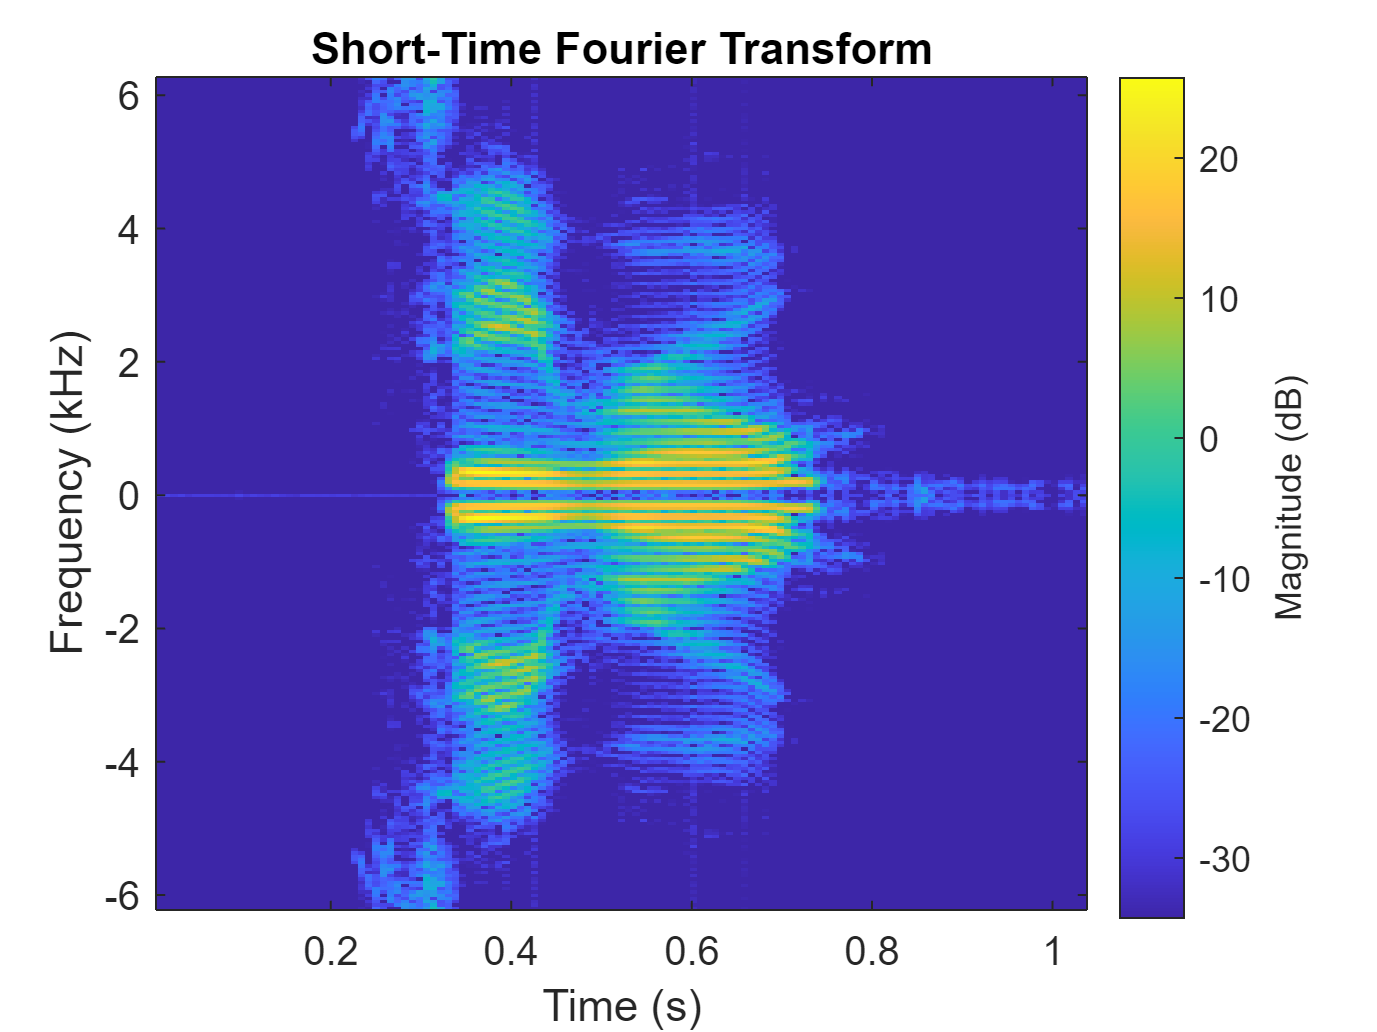

% s1
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s1.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)

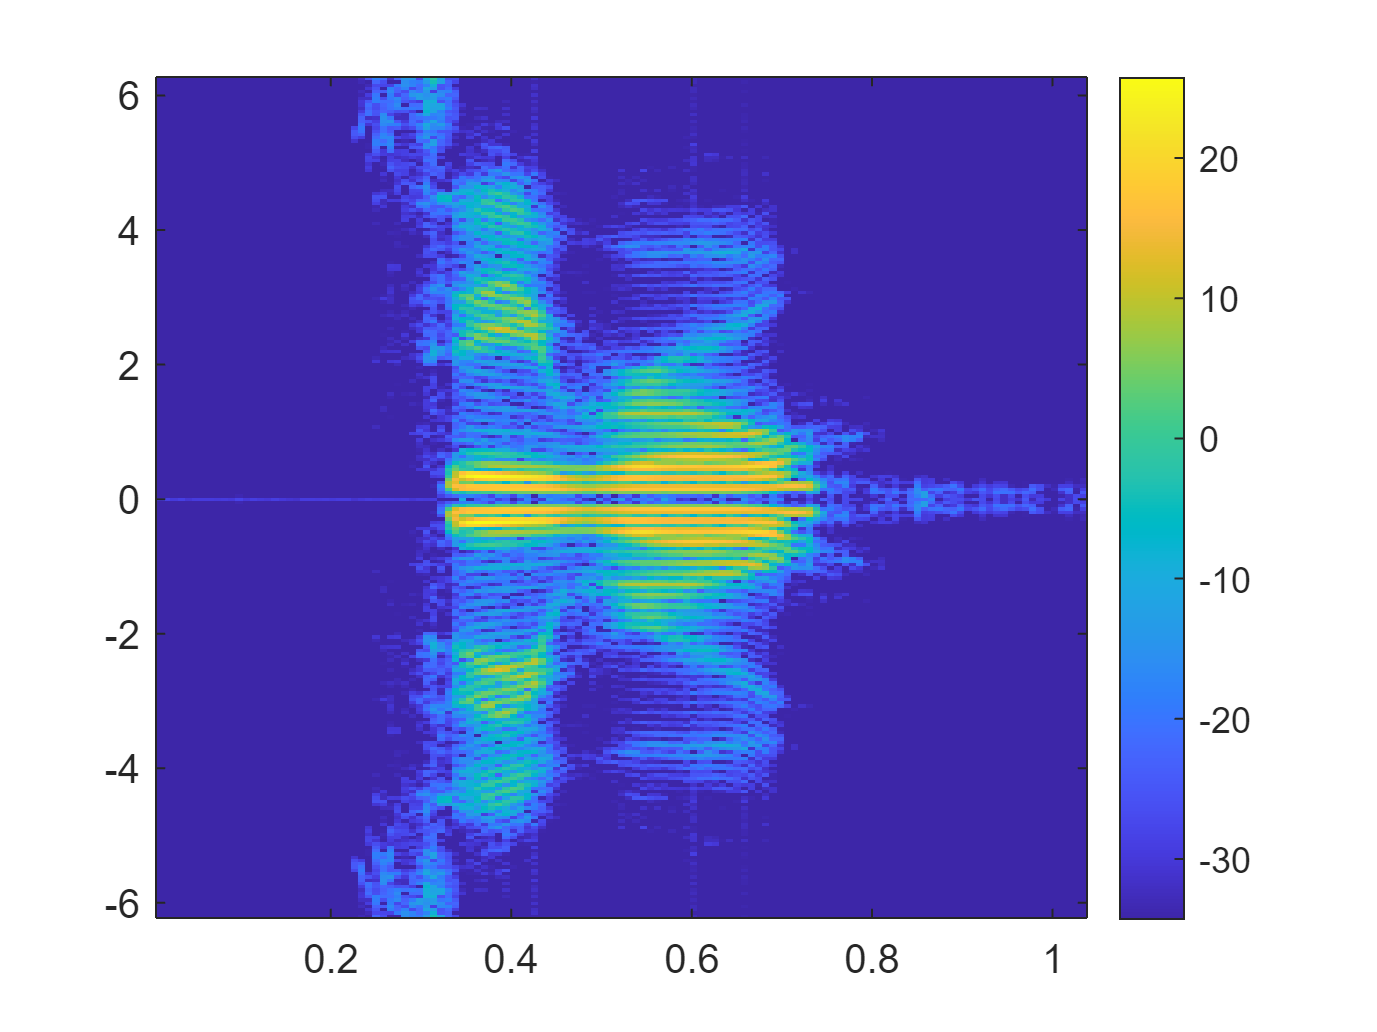

% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar

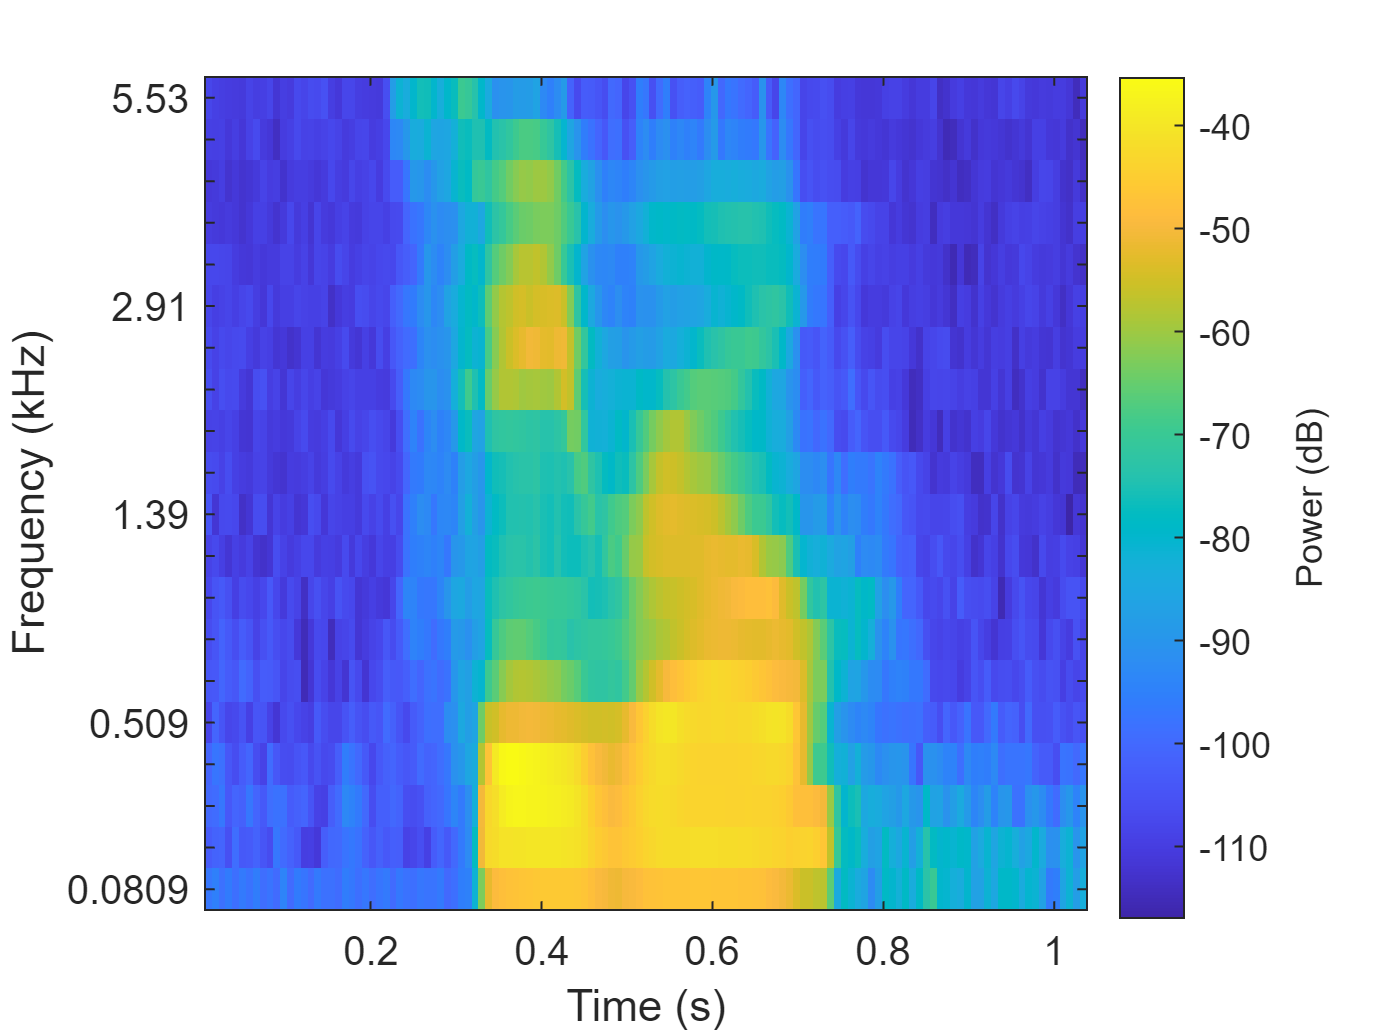

% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);

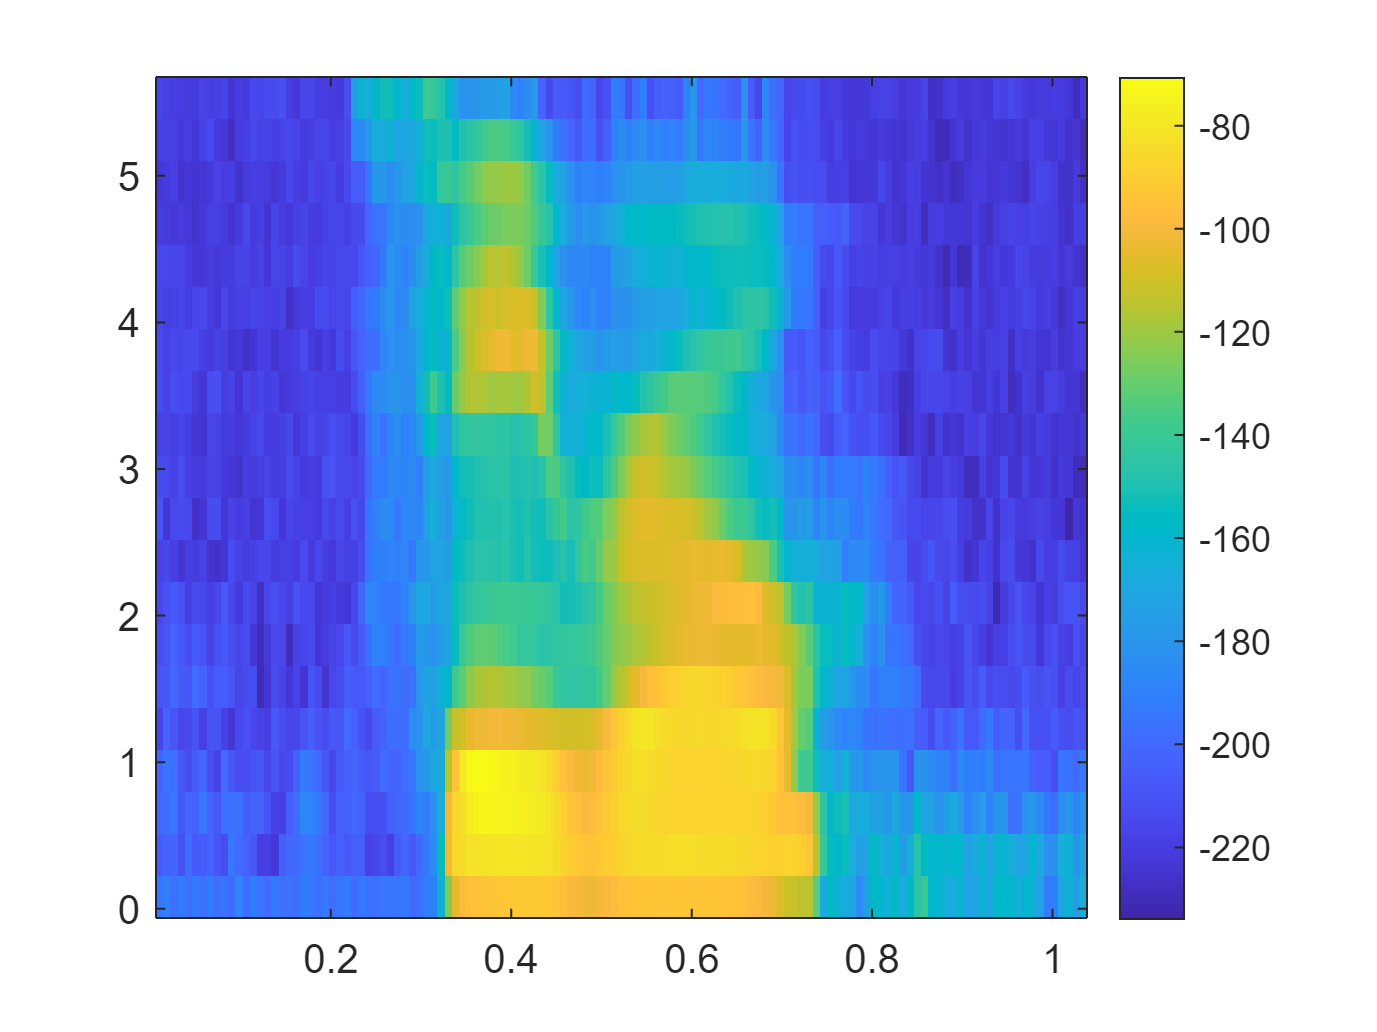

[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss));
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar

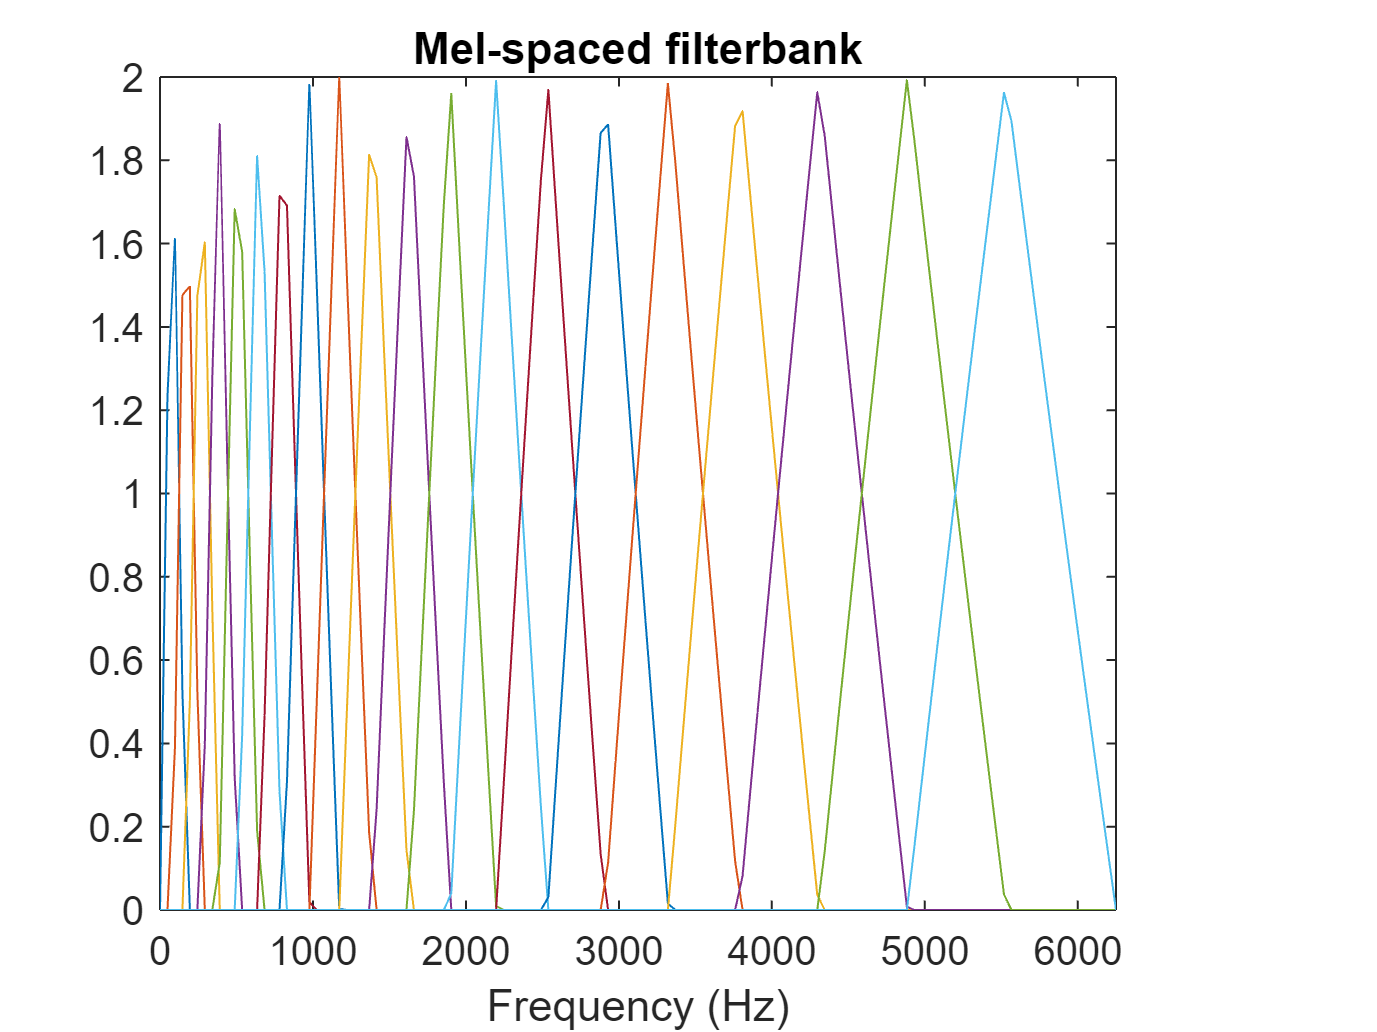

% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1));

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');

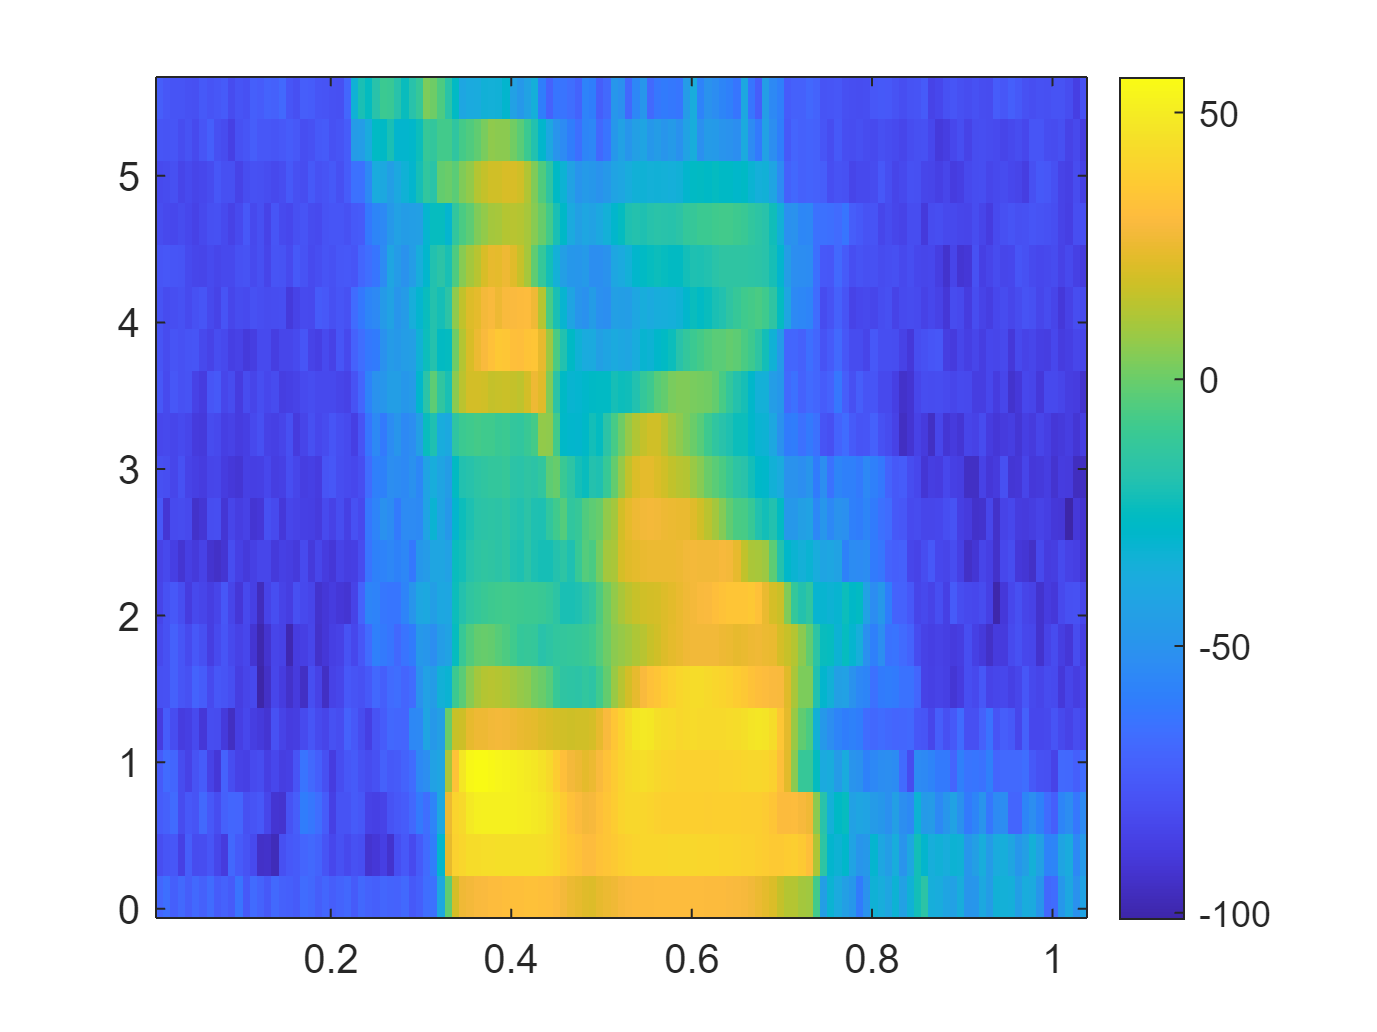

% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(n2-1:n)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some));
imagesc((T),(Ff/1000),some);
set(gca, 'YDir', 'normal');
view(2)
colorbar

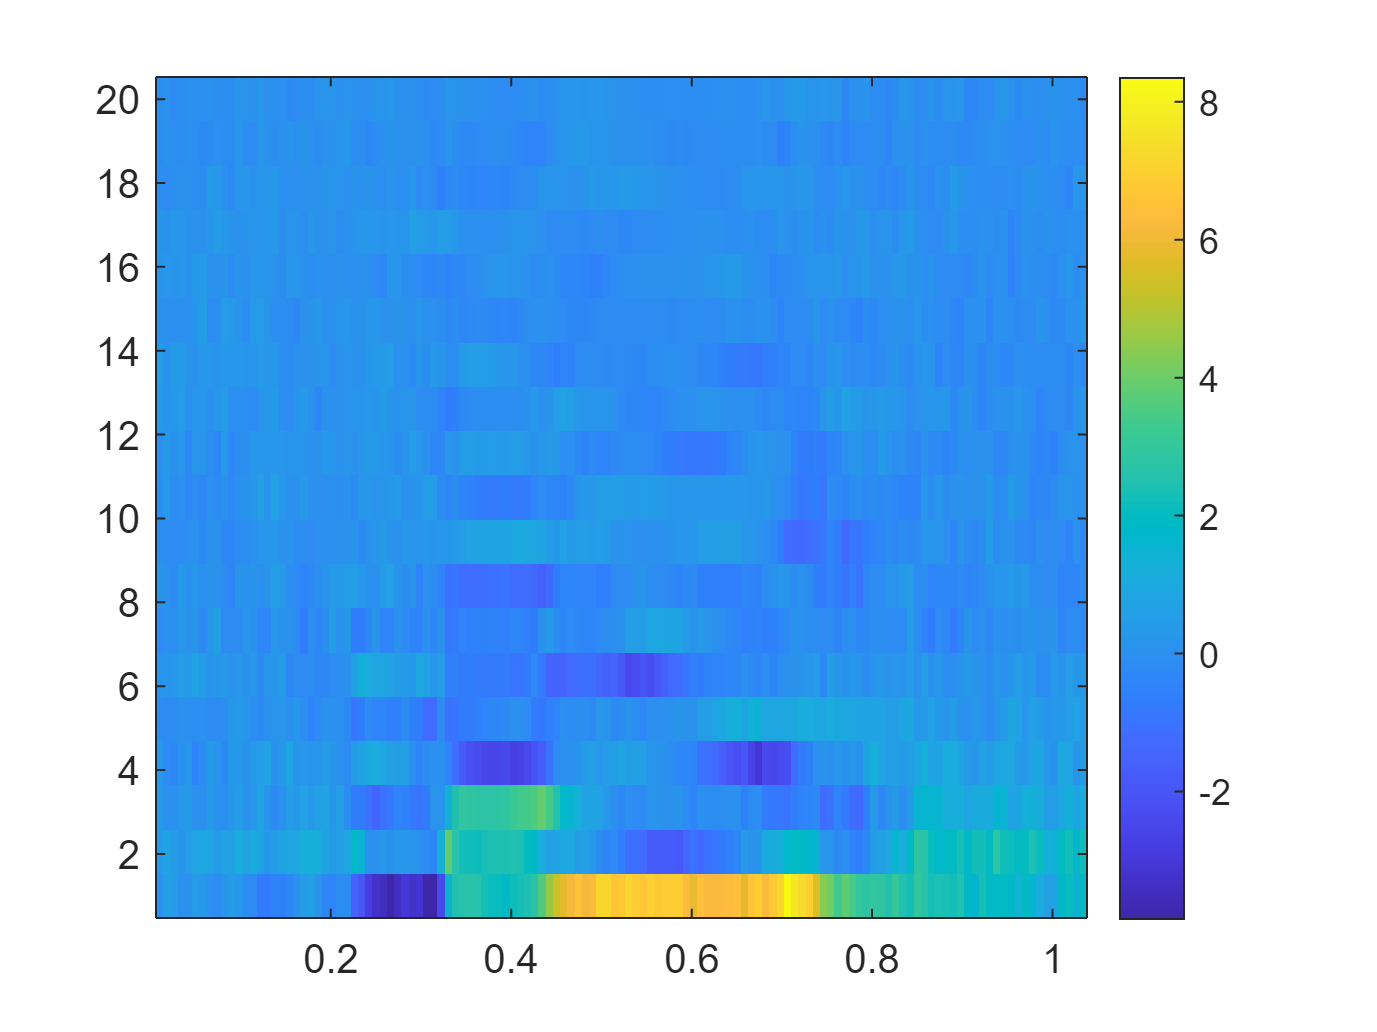

some = some / 20;
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(some(:,i));
    if i == 1
        y = [f(2:end)];
    else
        y = [y f(2:end)];
    end
end
%sdb = mag2db(abs(y));
y11 = y;
newf = 1:1:20;
imagesc(Tt,(newf)',y11);
set(gca, 'YDir', 'normal');
view(2)
colorbar

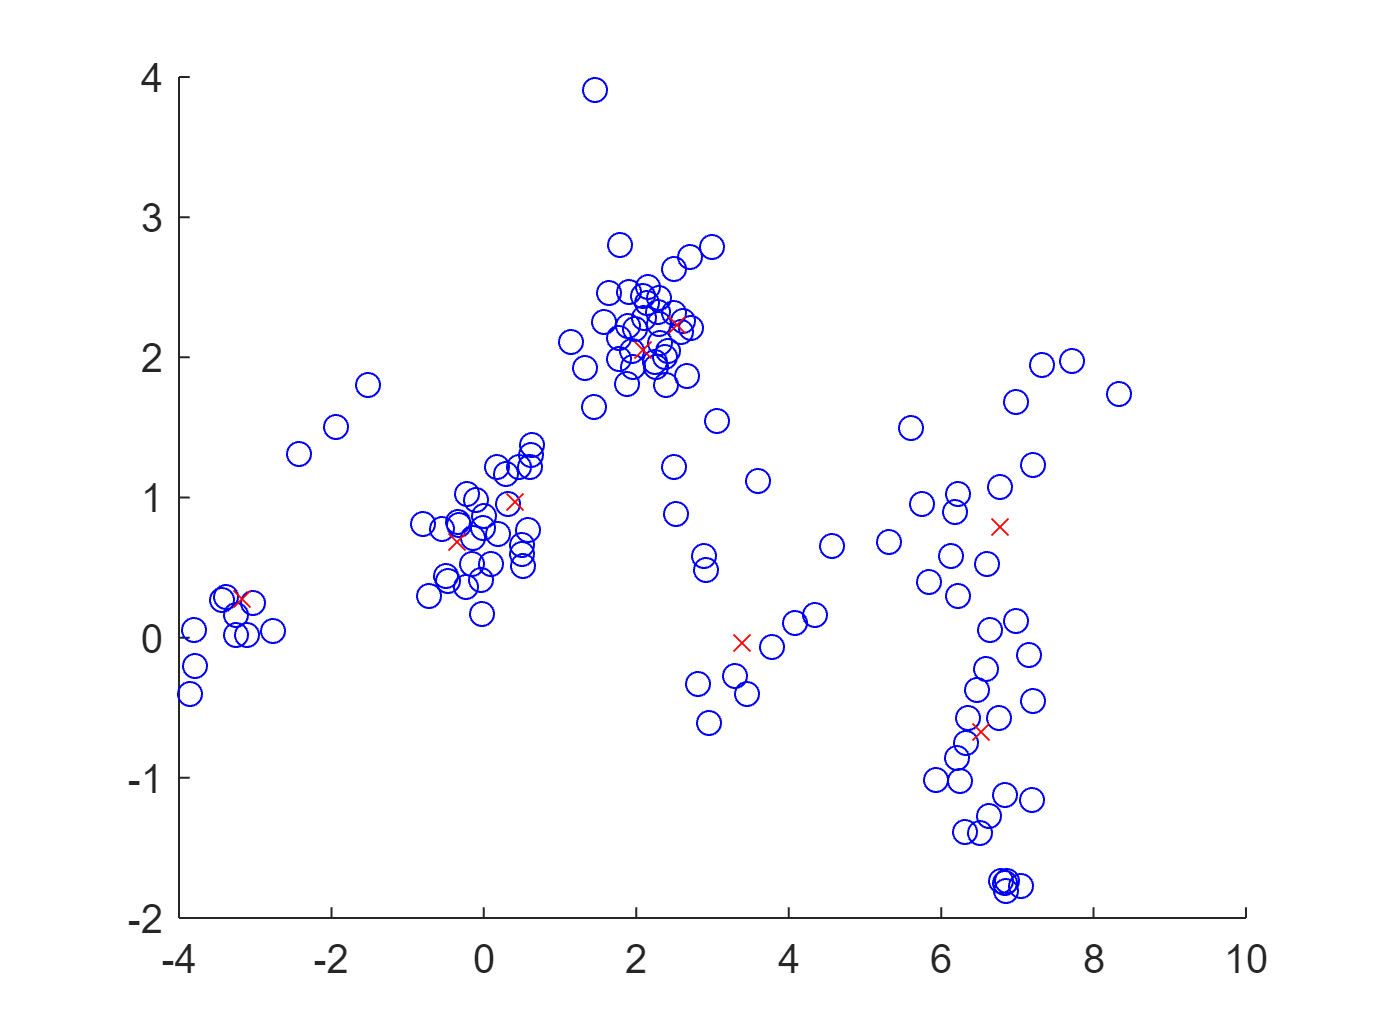

numCentroids = 8;
[dimensions,frames] = size(y11);
eplison = 0.001;
clusters = LBGAlgorithm(numCentroids,dimensions,frames,(y11)',eplison);

% end of dct part
% 1. run test signal through MFCC get those points
% 2. compare those values against the centroids from train data
% 3. use diseu and then do values then get groups matrix and then all non zero
% values get average
% 4. get sA average against s1 then do sA average against s2; whichever is
% less that is the signal

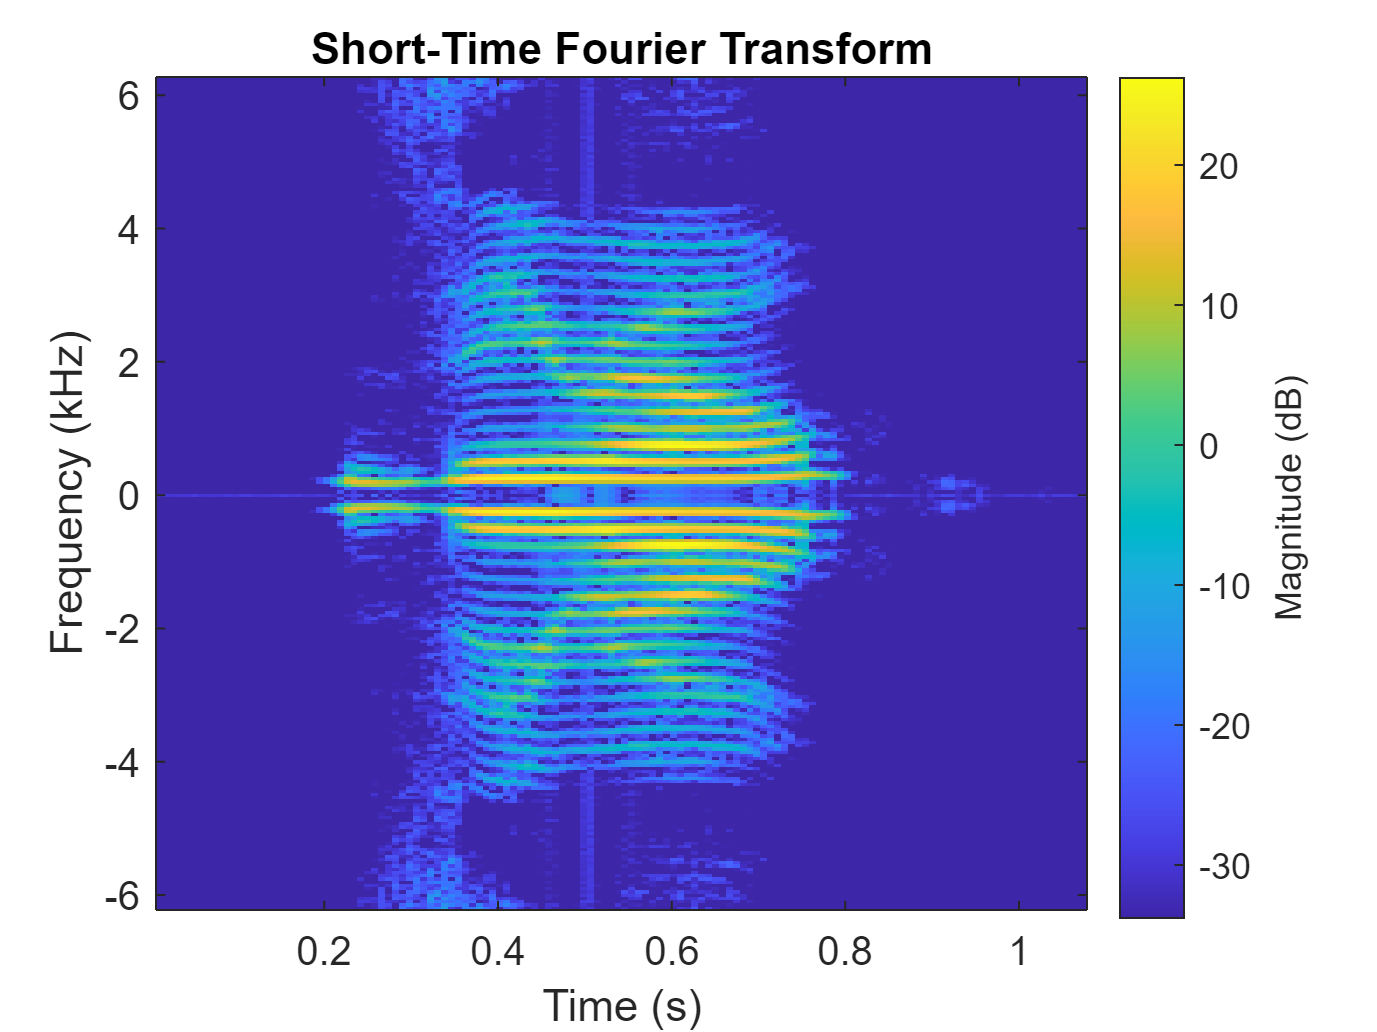

% s2
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s2.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)

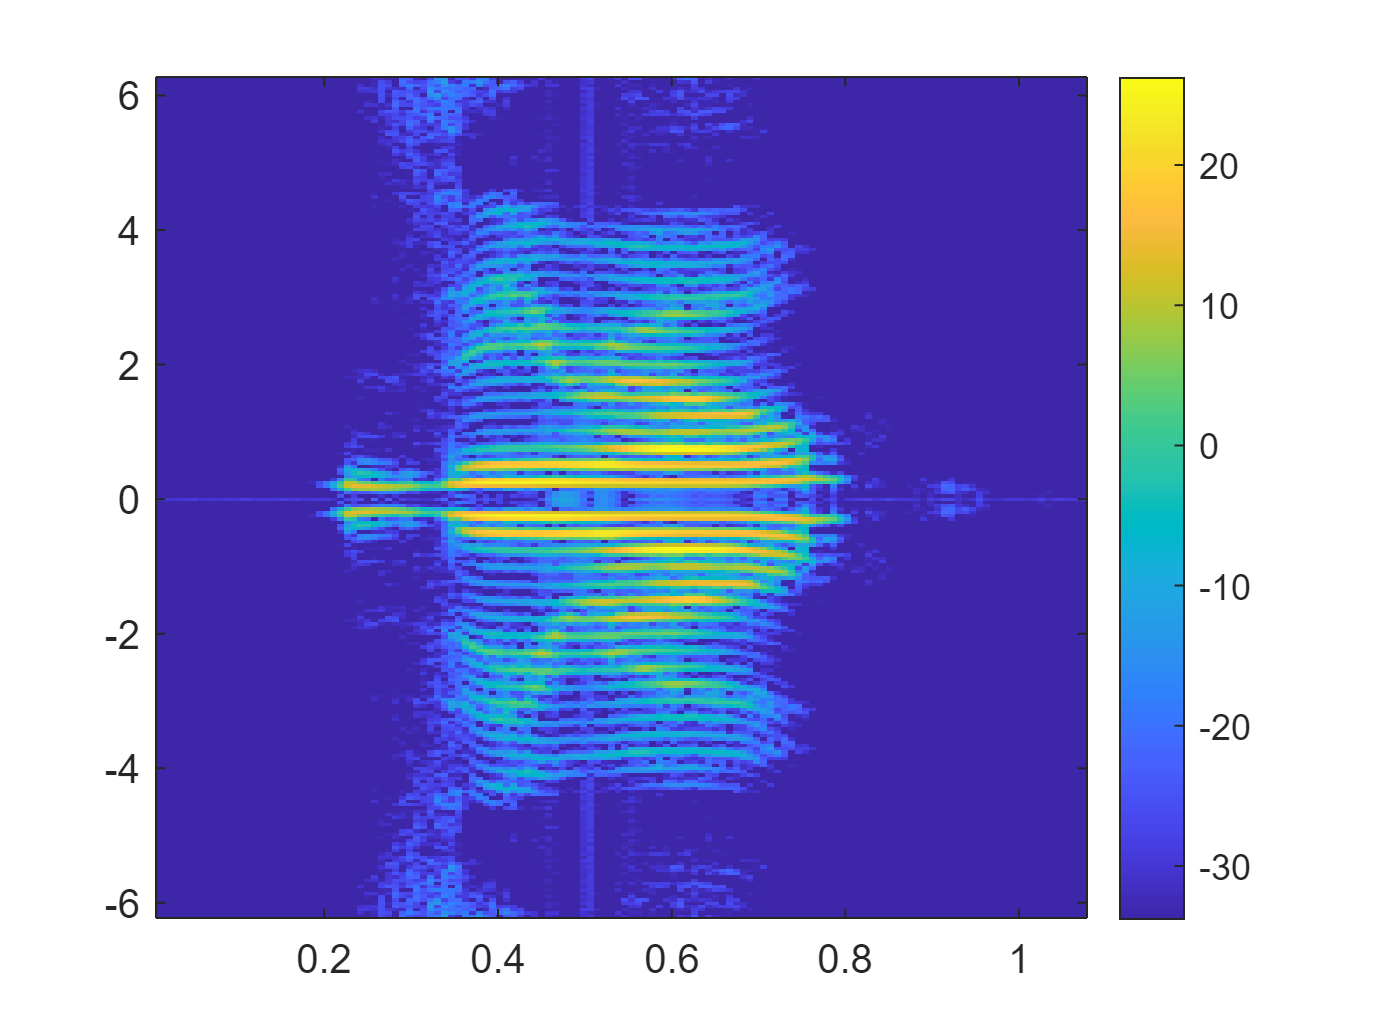

% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar

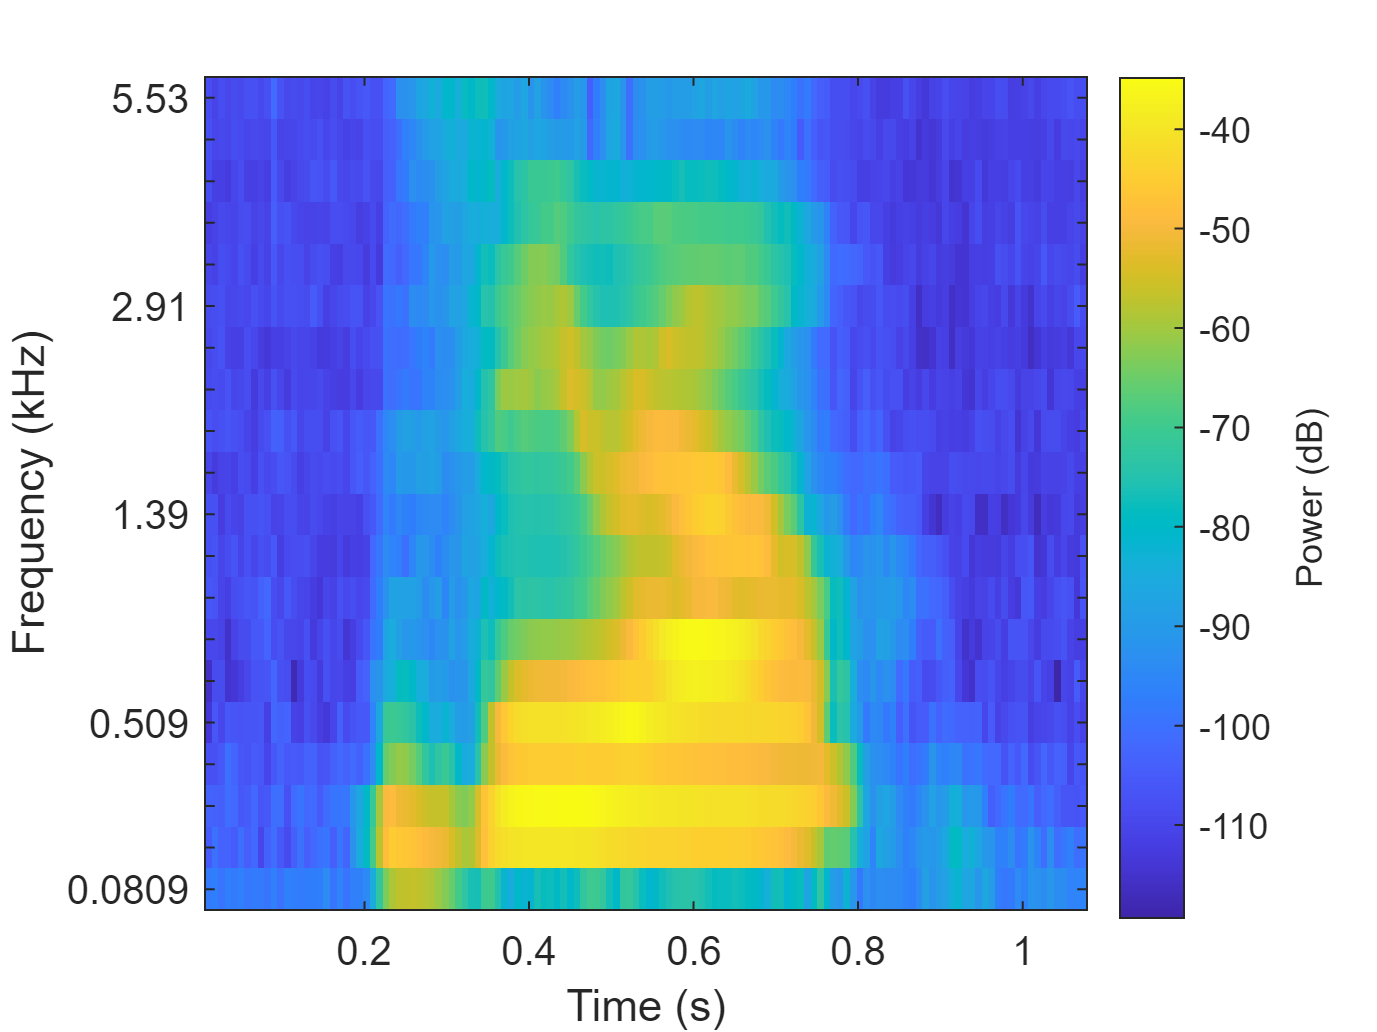

% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);

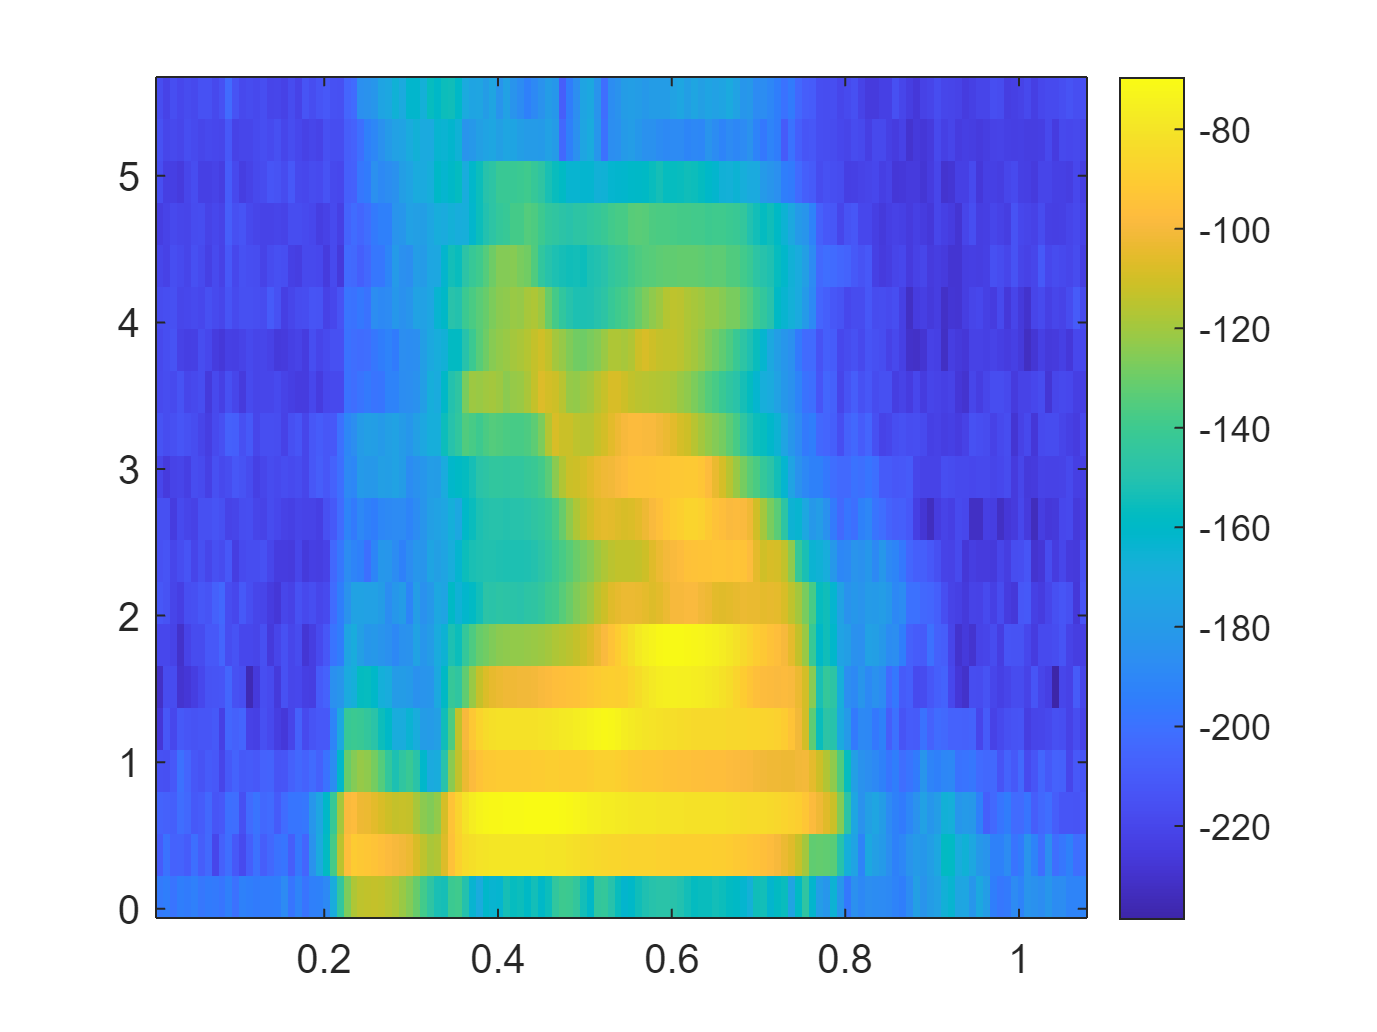

[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss));
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar

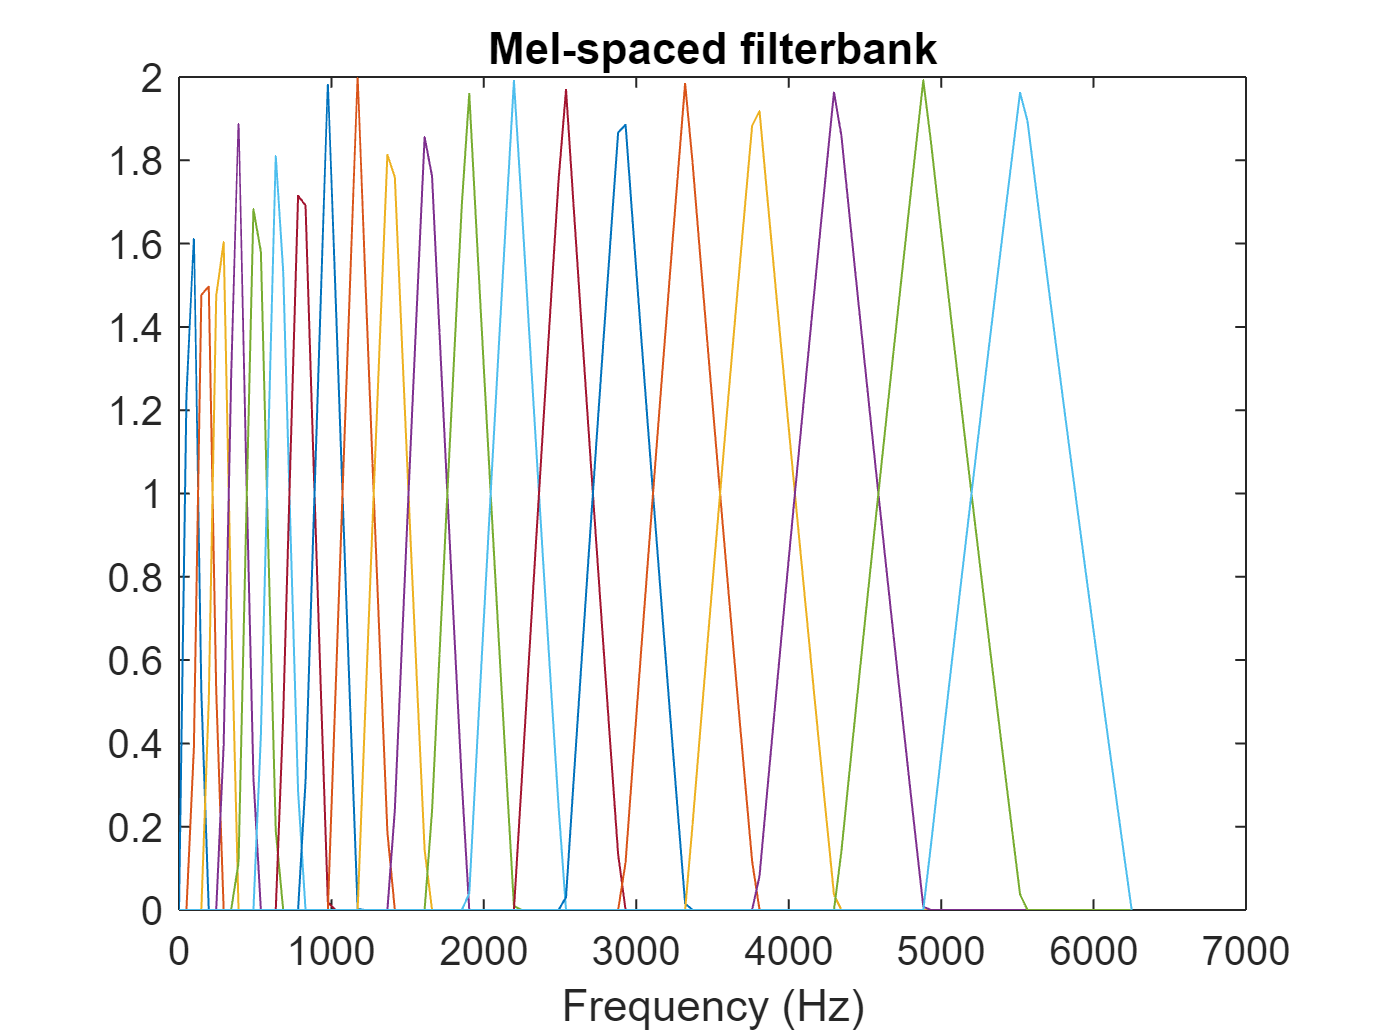

% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1));

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');

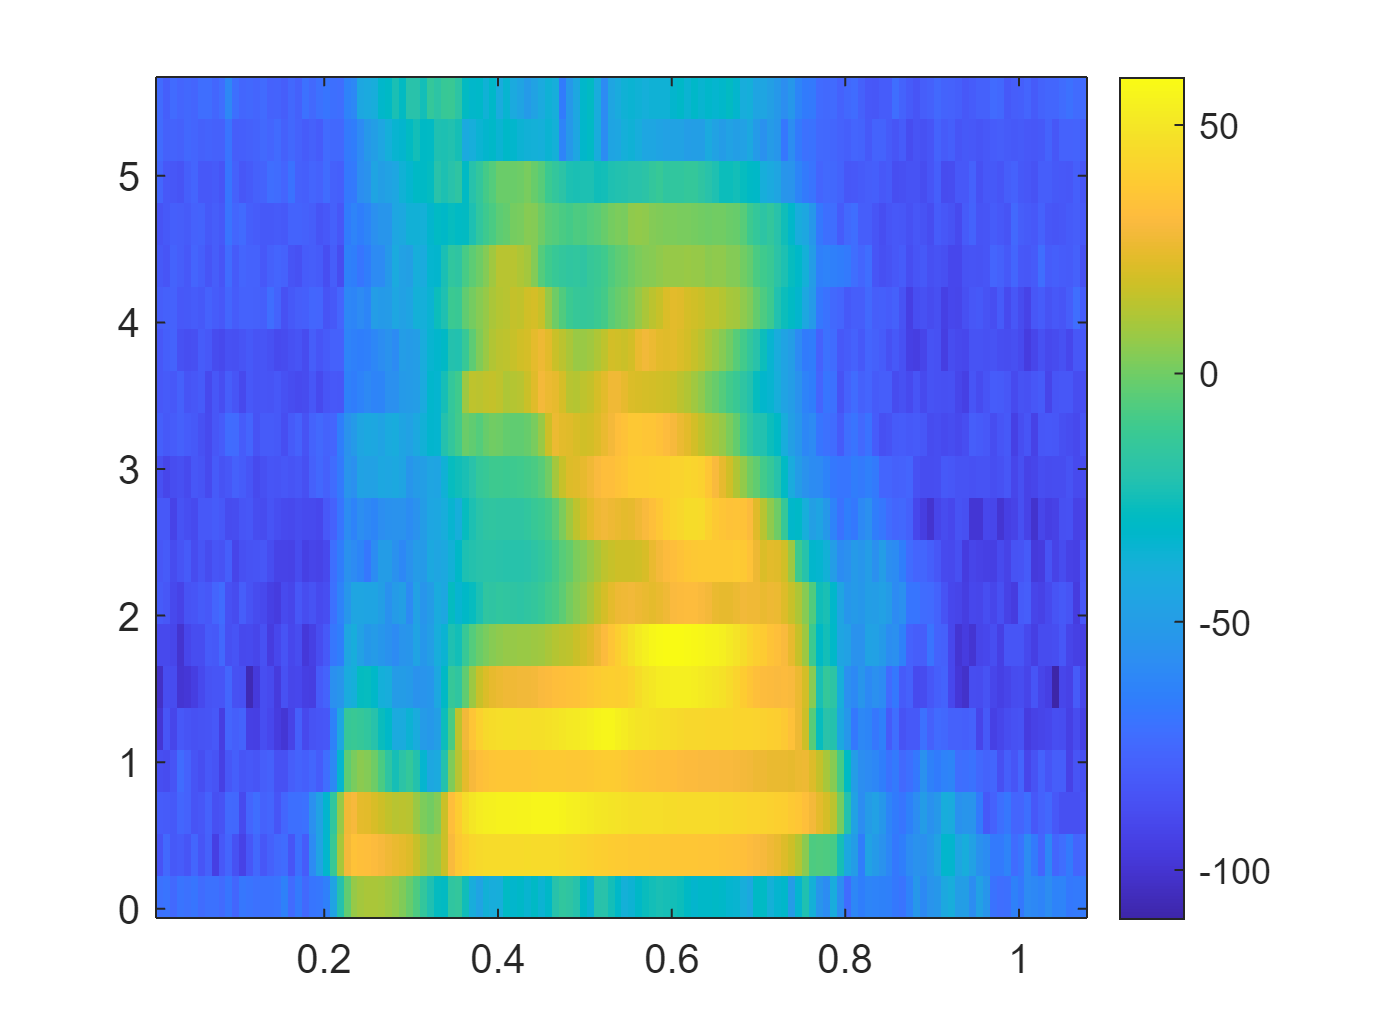

% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(n2-1:n)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some));
imagesc((T),(Ff/1000),some);
set(gca, 'YDir', 'normal');
view(2)
colorbar

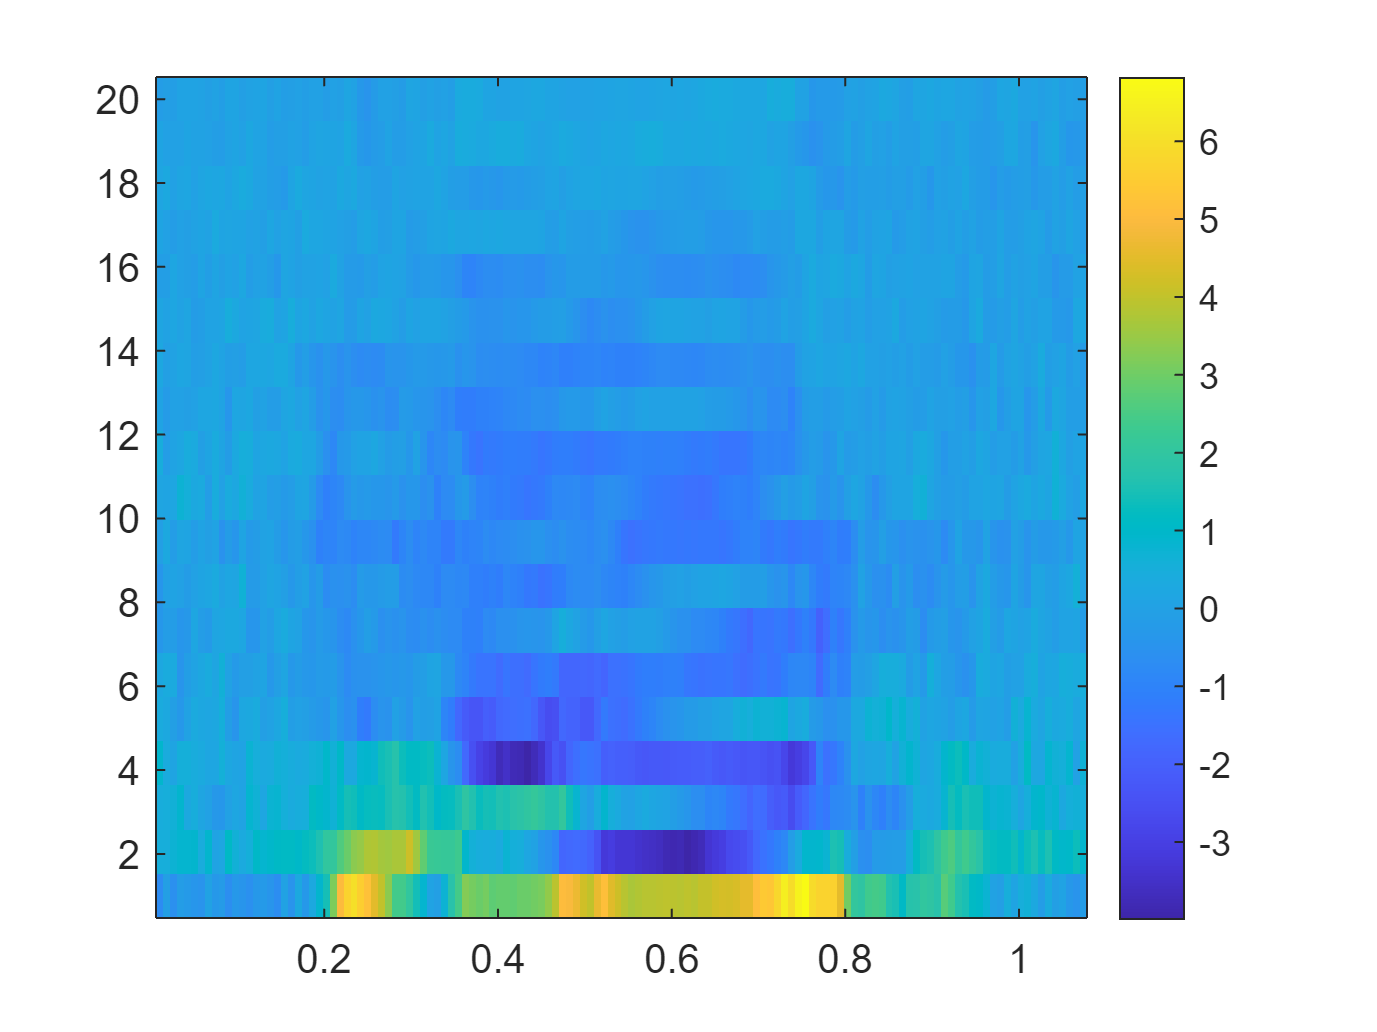

some = some / 20;
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(some(:,i));
    if i == 1
        y = [f(2:end)];
    else
        y = [y f(2:end)];
    end
end
%sdb = mag2db(abs(y));
y22 = y;
newf = 1:1:20;
imagesc(T,(newf)',y22);
set(gca, 'YDir', 'normal');
view(2)
colorbar

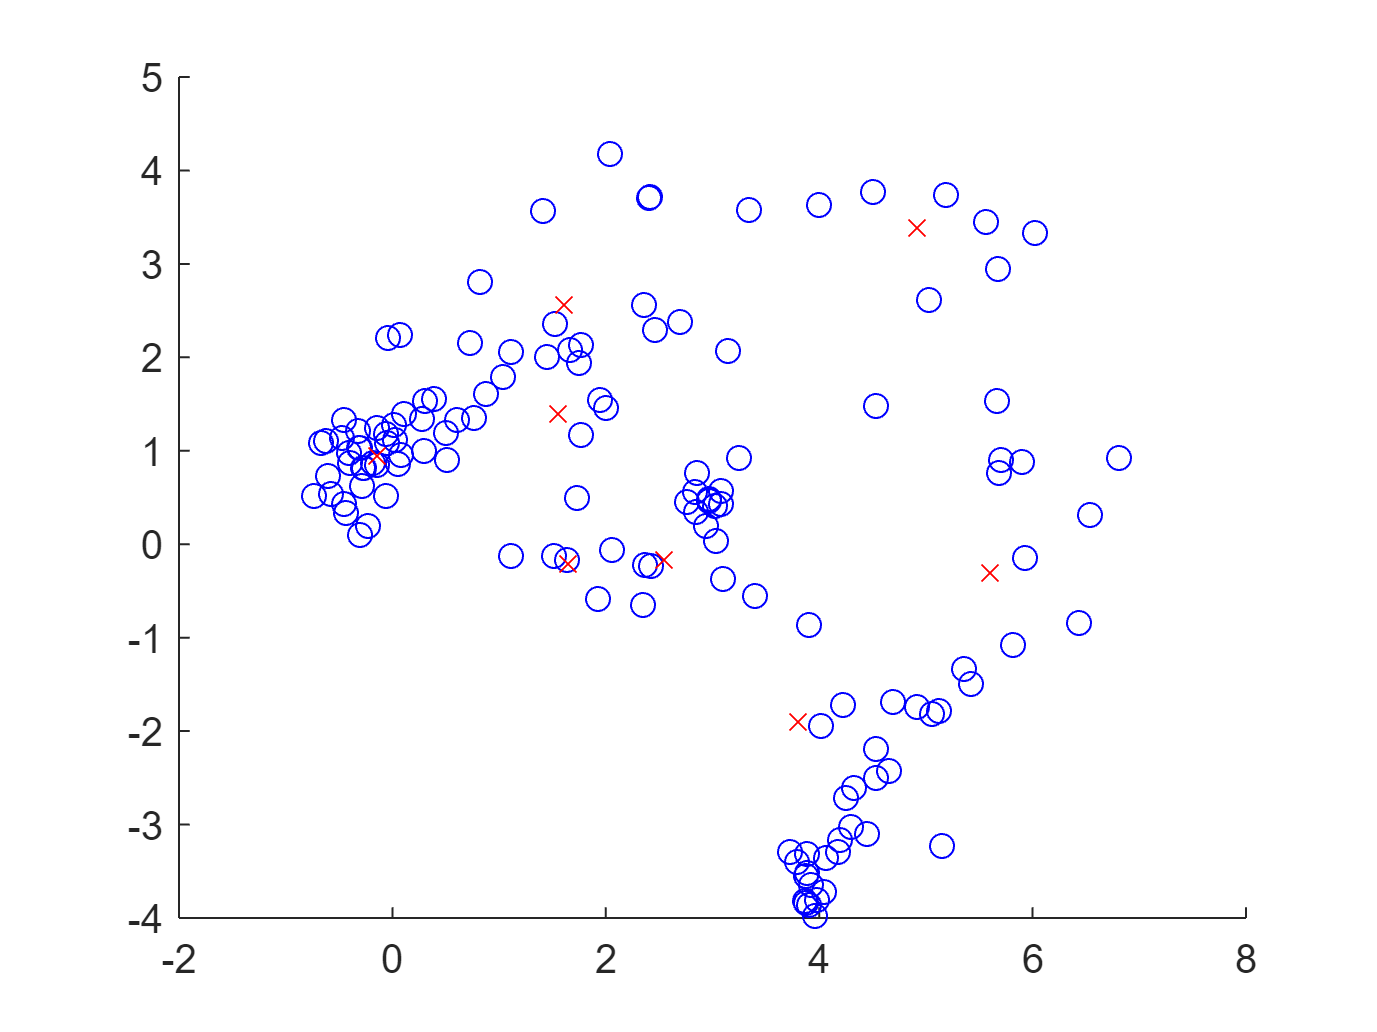

% end of dct part
numCentroids = 8;
[dimensions,frames] = size(y22);
eplison = 0.001;
clusters1 = LBGAlgorithm(numCentroids,dimensions,frames,(y22)',eplison);

% scatter(y22(4,:),y22(5,:),'b','o')
% hold on;
% scatter(y11(4,:),y11(5,:),'r','x')
% hold on;
% scatter(clusters1(:,4),clusters1(:,5),'black','*')
% hold on;
% scatter(clusters(:,4),clusters(:,5),'g','*')
% hold off;

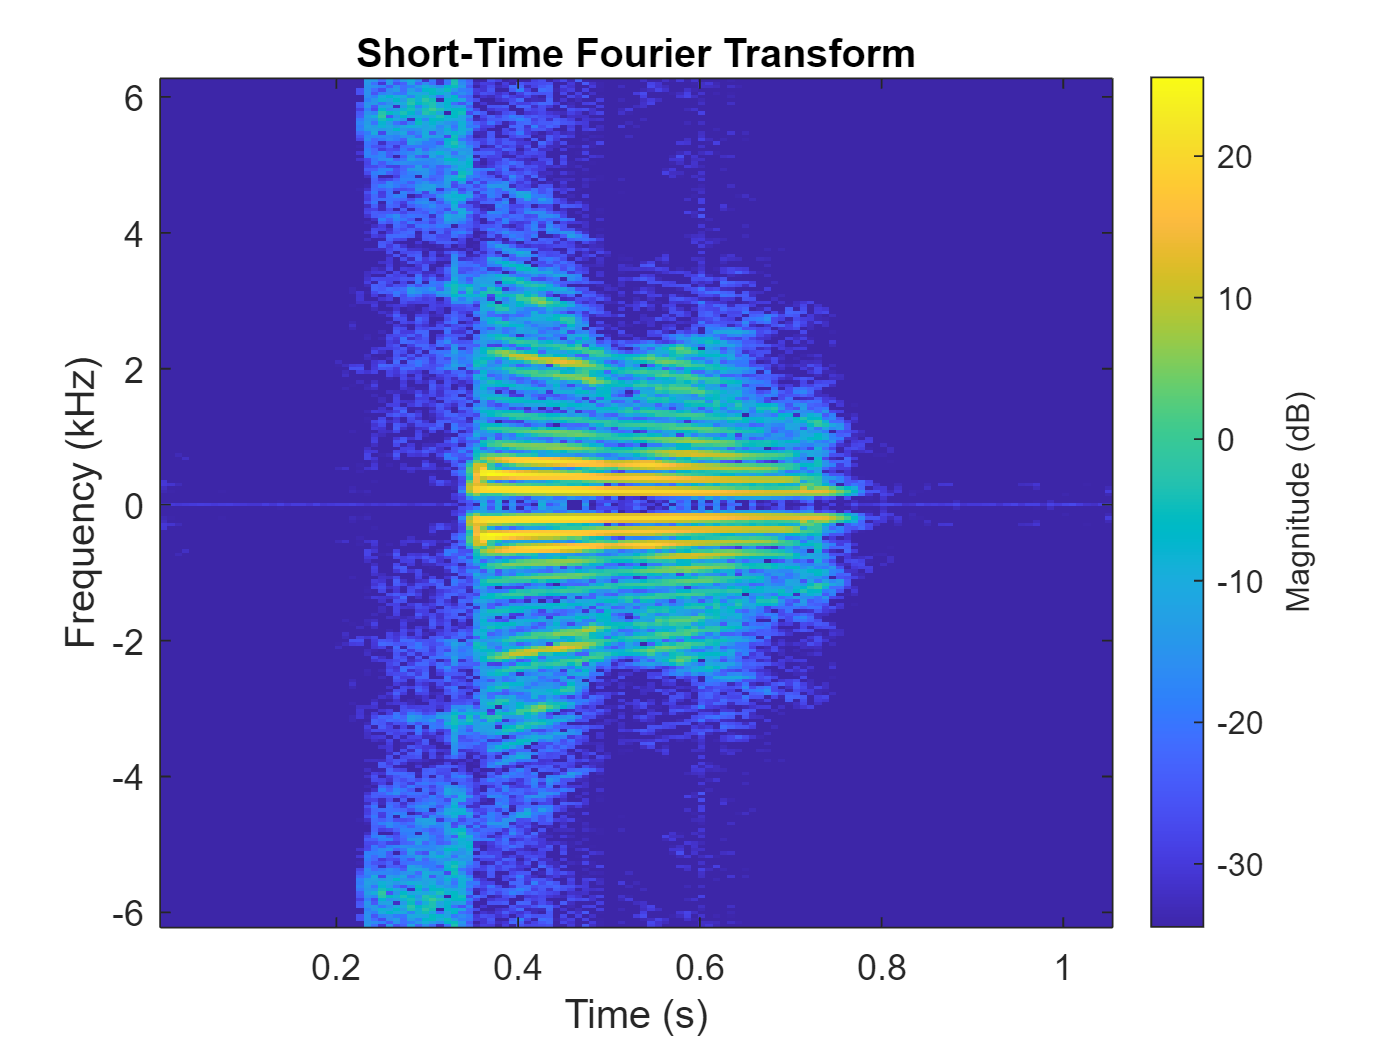

% s3
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s3.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)

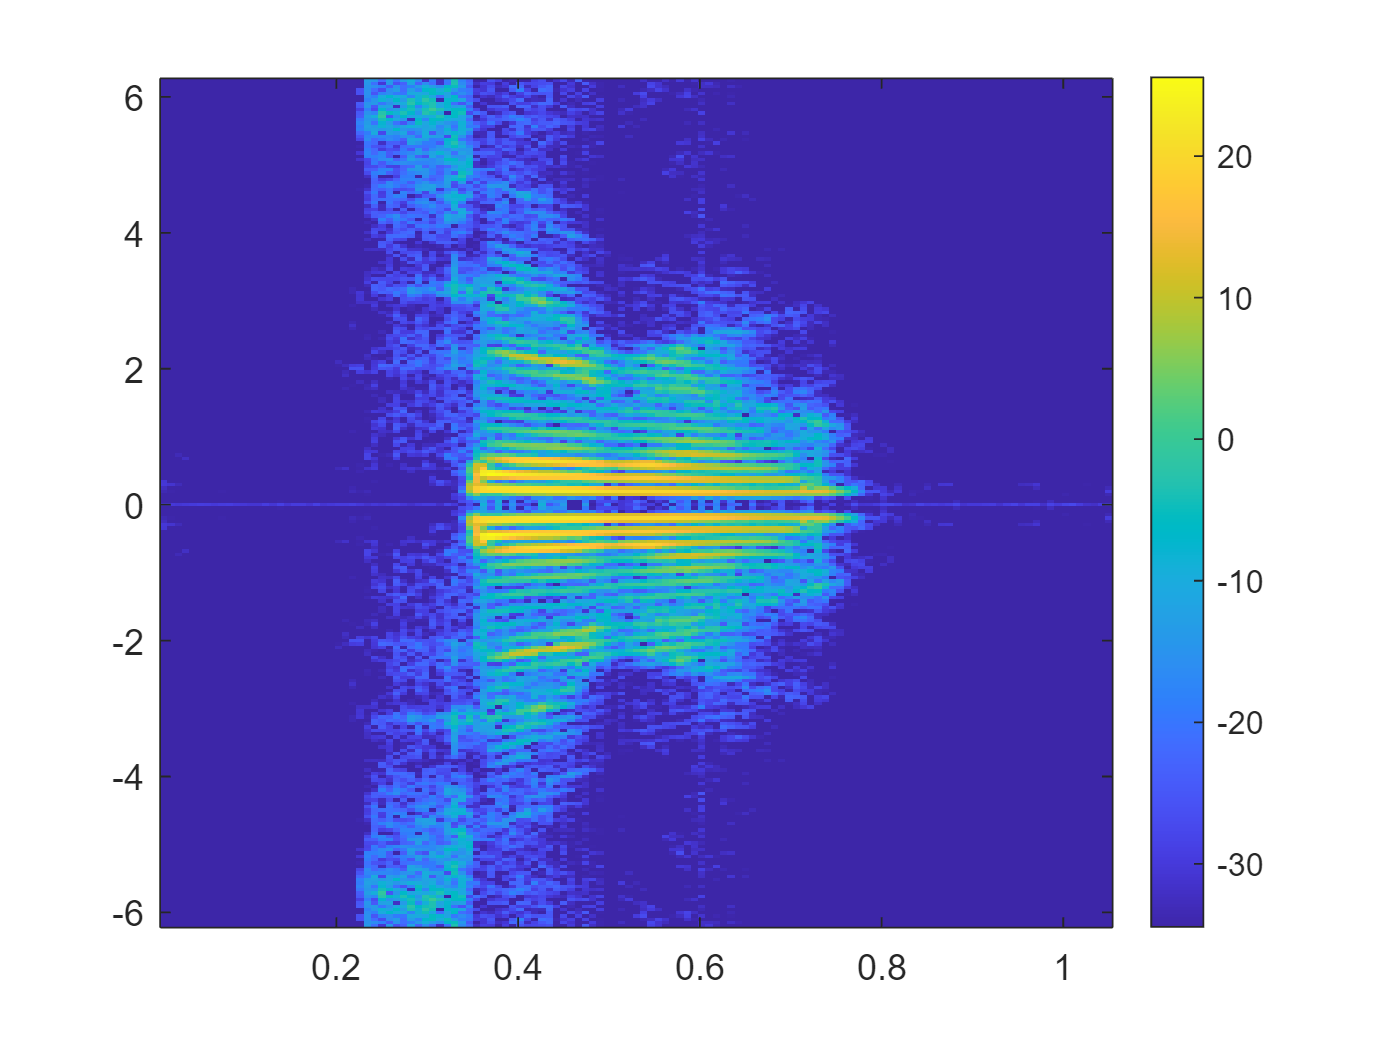

% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar

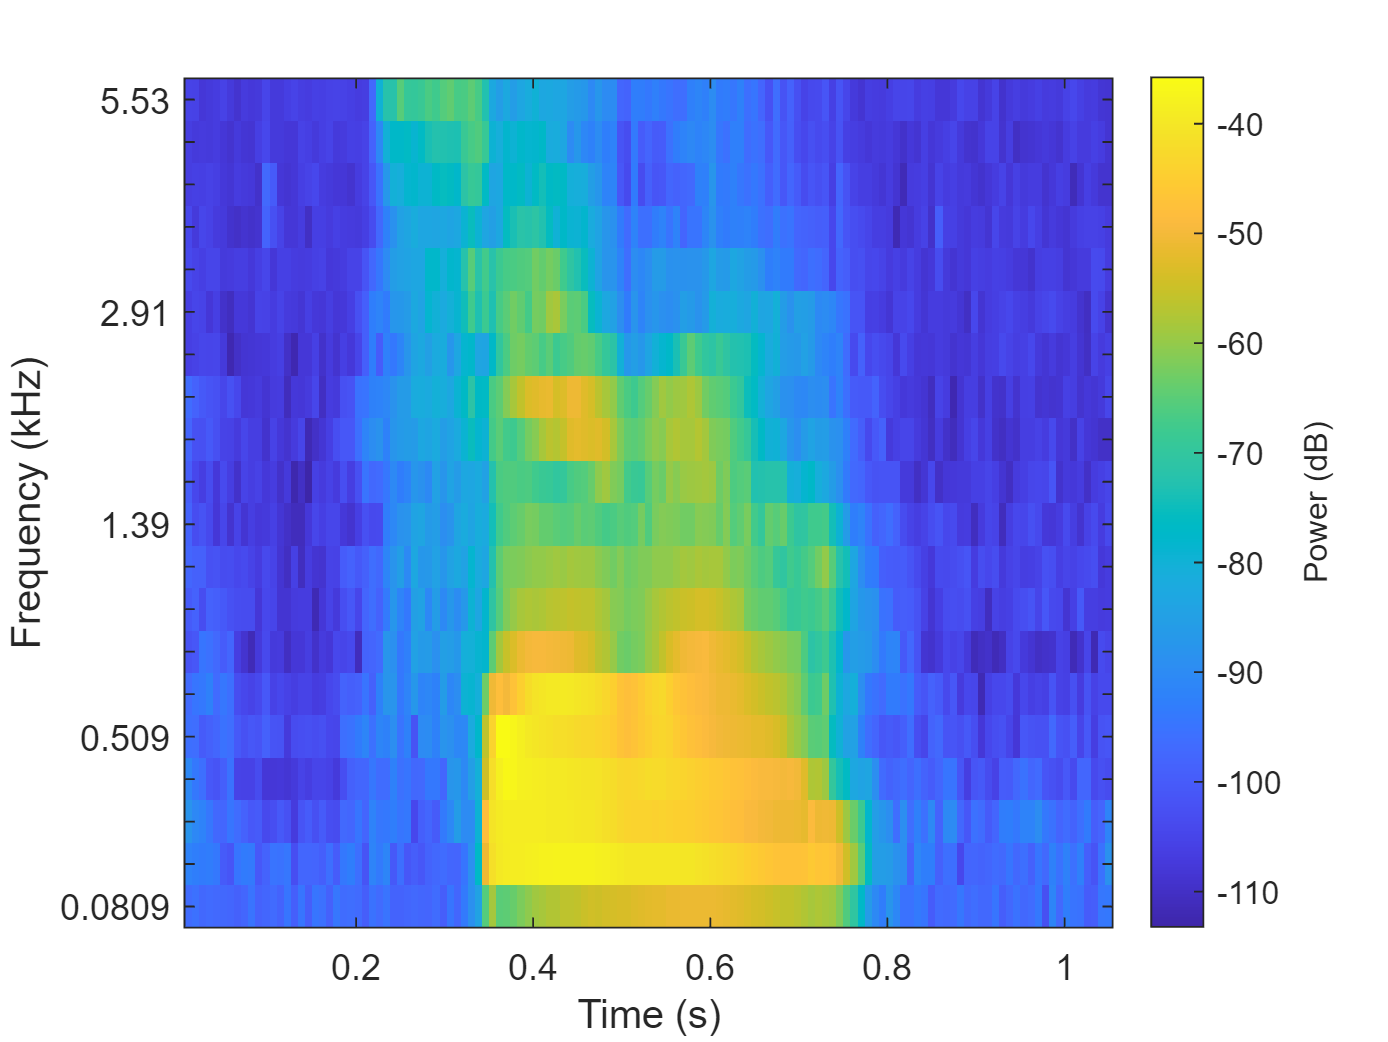

% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);

[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))

sdb1 =  -192.7320 -190.9102 -194.5622 -193.7420 -194.3110 -194.9148 -195.3431 -197.5250 -195.0980 -189.9306 -197.0201 -194.9867 -193.4886 -196.3562 -189.0702 -198.1985 -189.2433 -198.9902 -188.9506 -190.8094 -197.5939 -188.3945 -192.7089 -191.9799 -193.4917 -198.6717 -190.2918 -193.5779 -189.6042 -196.4768 -196.7510 -195.2336 -194.2267 -195.1701 -195.9662 -193.0287 -199.1369 -189.3927 -194.9903 -187.4557 -177.4761 -168.4406 -130.9652 -117.5082 -129.6539 -129.0455 -127.6804 -123.5785 -120.9477 -118.0226
 -183.7607 -185.4152 -186.6312 -186.2673 -187.8536 -200.2650 -202.3483 -189.1322 -187.0694 -187.3165 -201.0855 -196.3764 -189.6377 -190.6096 -188.8648 -205.5497 -195.4371 -195.1602 -195.5708 -198.5283 -191.7028 -199.4679 -188.0631 -185.8420 -191.7837 -203.0308 -183.0206 -187.5982 -182.2852 -200.7581 -191.6862 -201.9600 -199.0126 -201.9597 -196.2394 -194.9047 -192.6472 -194.9674 -195.5756 -189.4626 -177.8869 -153.2711 -101.3156  -82.6945  -78.9060  -77.7127  -77.2702  -77.0088  -76.4520  

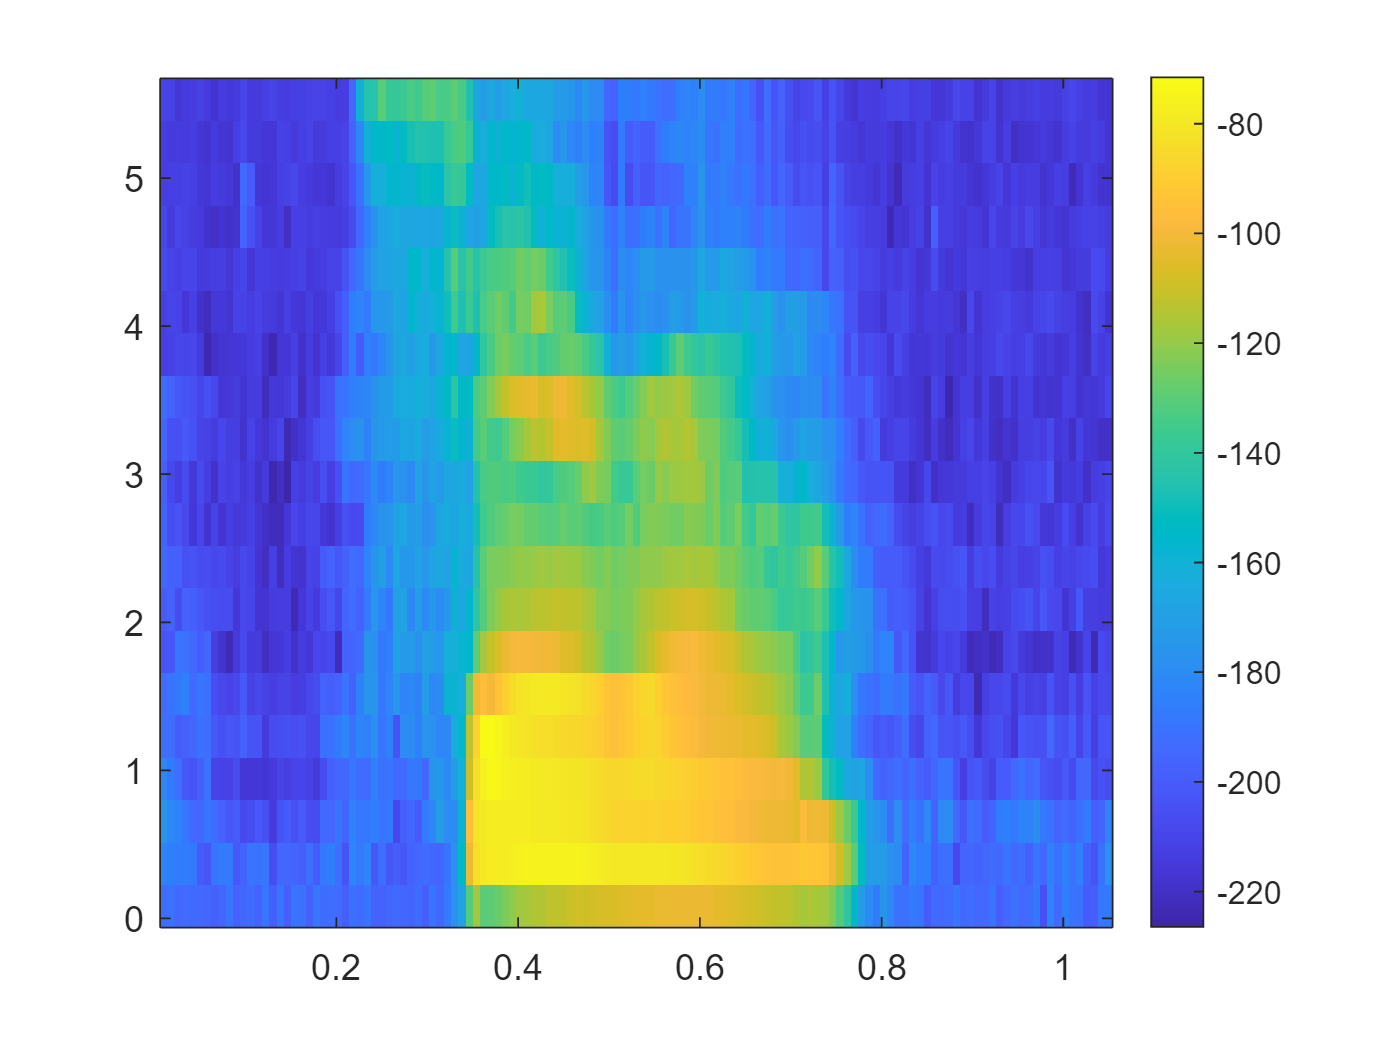

imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar

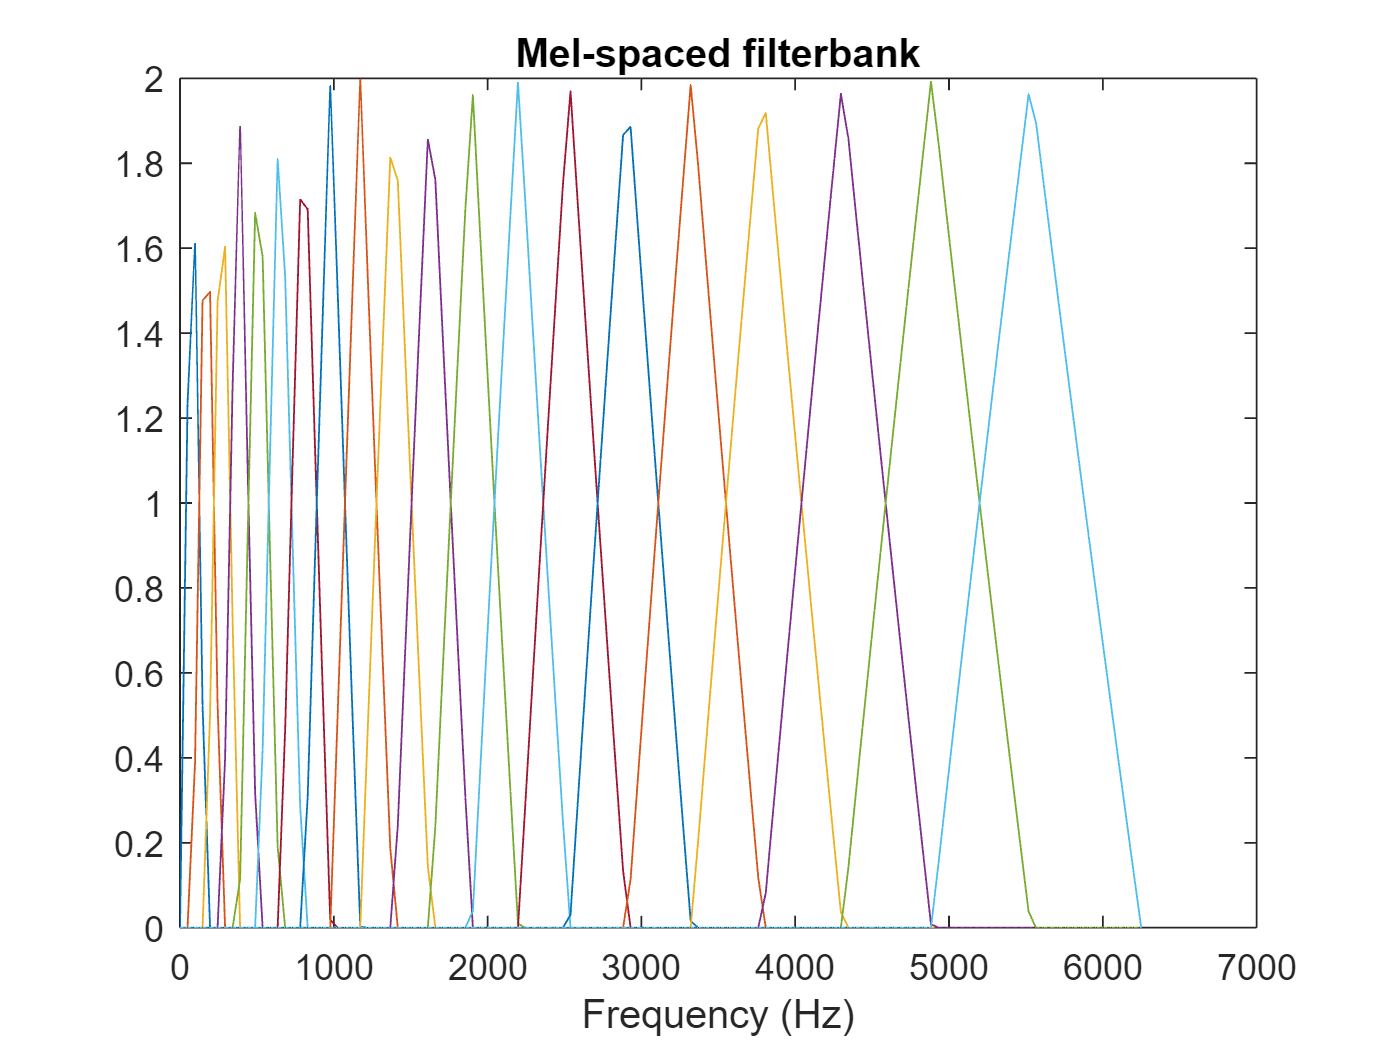

% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
m = melfb(p,n,fs);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');

% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some));

some =   -83.9178  -95.1723  -94.6006  -90.7906  -92.8309  -87.5112  -84.3009 -102.5182  -80.2057  -93.8472  -97.6156  -89.1382  -92.4018  -93.8620  -90.1299  -85.8565 -100.4867  -88.3091  -88.9464  -87.6273  -88.8607  -82.5351  -93.2787  -90.9865  -95.9061  -93.2071  -70.9605  -45.3064  -20.0319  -27.2569  -30.2788  -24.9402  -18.6679  -31.5285  -16.5697  -18.0275   -6.1197   -3.6325  -10.9294   -2.1270   -6.8604  -21.3210  -31.8052  -51.5763  -48.6310  -41.4991  -56.4471  -54.9361  -36.3775  -30.0244
  -85.9631  -90.6288  -88.9978  -93.7381  -90.3984  -83.2946  -89.4502 -103.9312  -84.5553  -94.2147 -106.5775  -80.2595  -84.8415  -97.9932  -91.6731  -82.7556  -98.3342  -90.6711  -80.2919  -78.5779  -81.8684  -90.2366  -95.4598  -83.5561  -84.7023  -93.4025  -71.7100  -45.9232  -20.0348  -26.3730  -12.0448   -8.7782  -10.2056  -15.0889   -7.7054   -7.8285    0.4374   -1.7096  -11.1007   -7.4902   -7.1129  -20.9405  -30.1411  -50.1793  -45.7063  -46.2183  -50.0274  -41.7204  -46.5636  

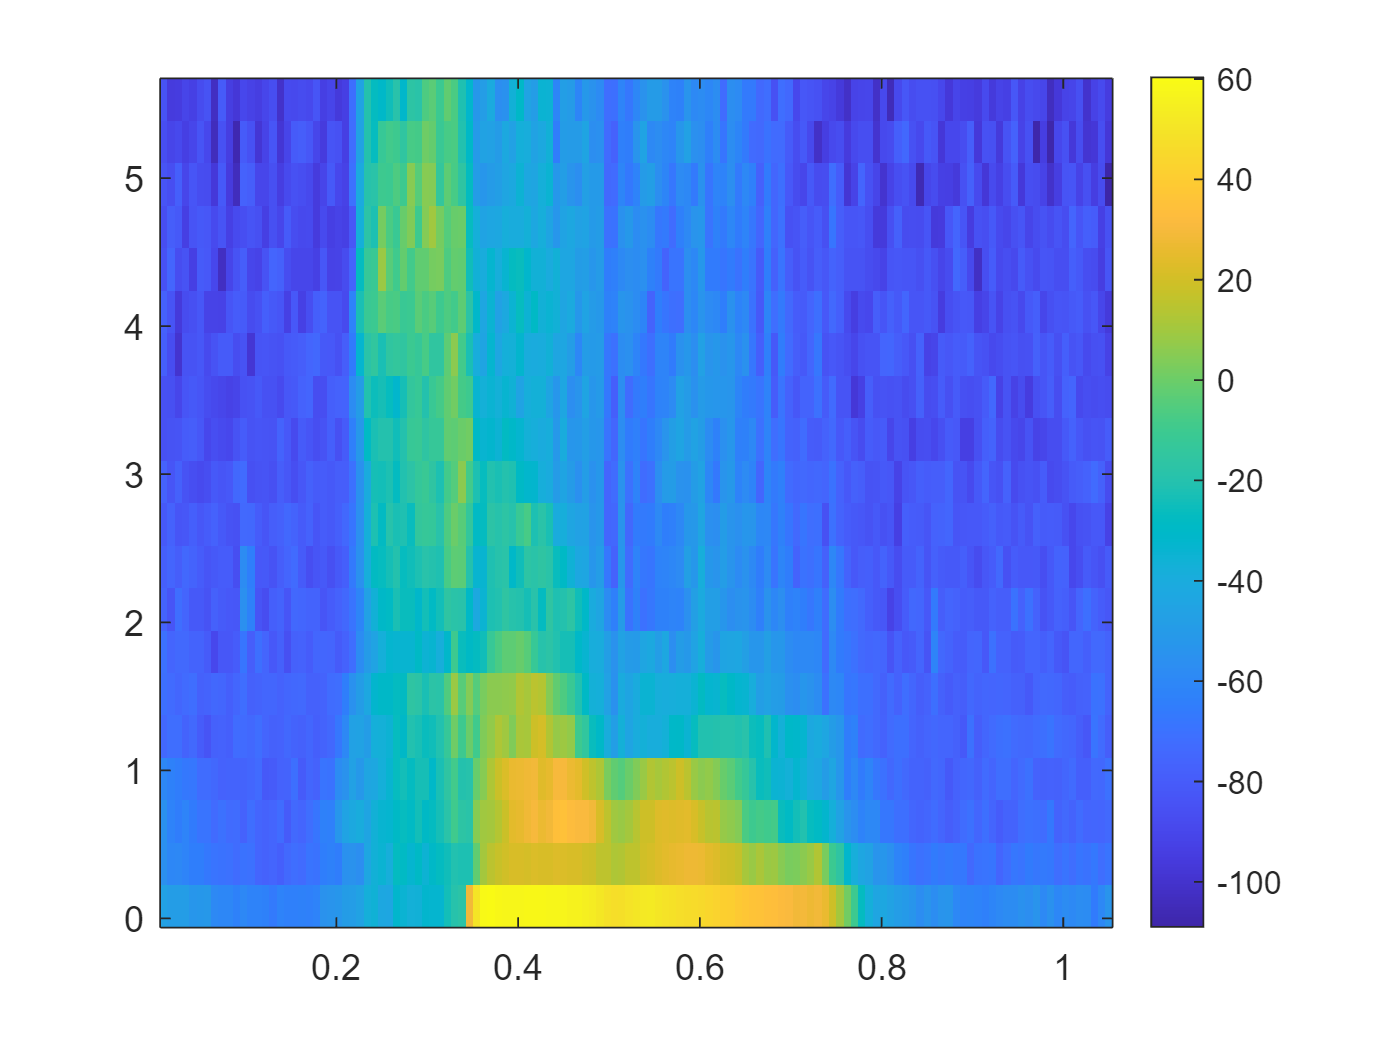

imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar

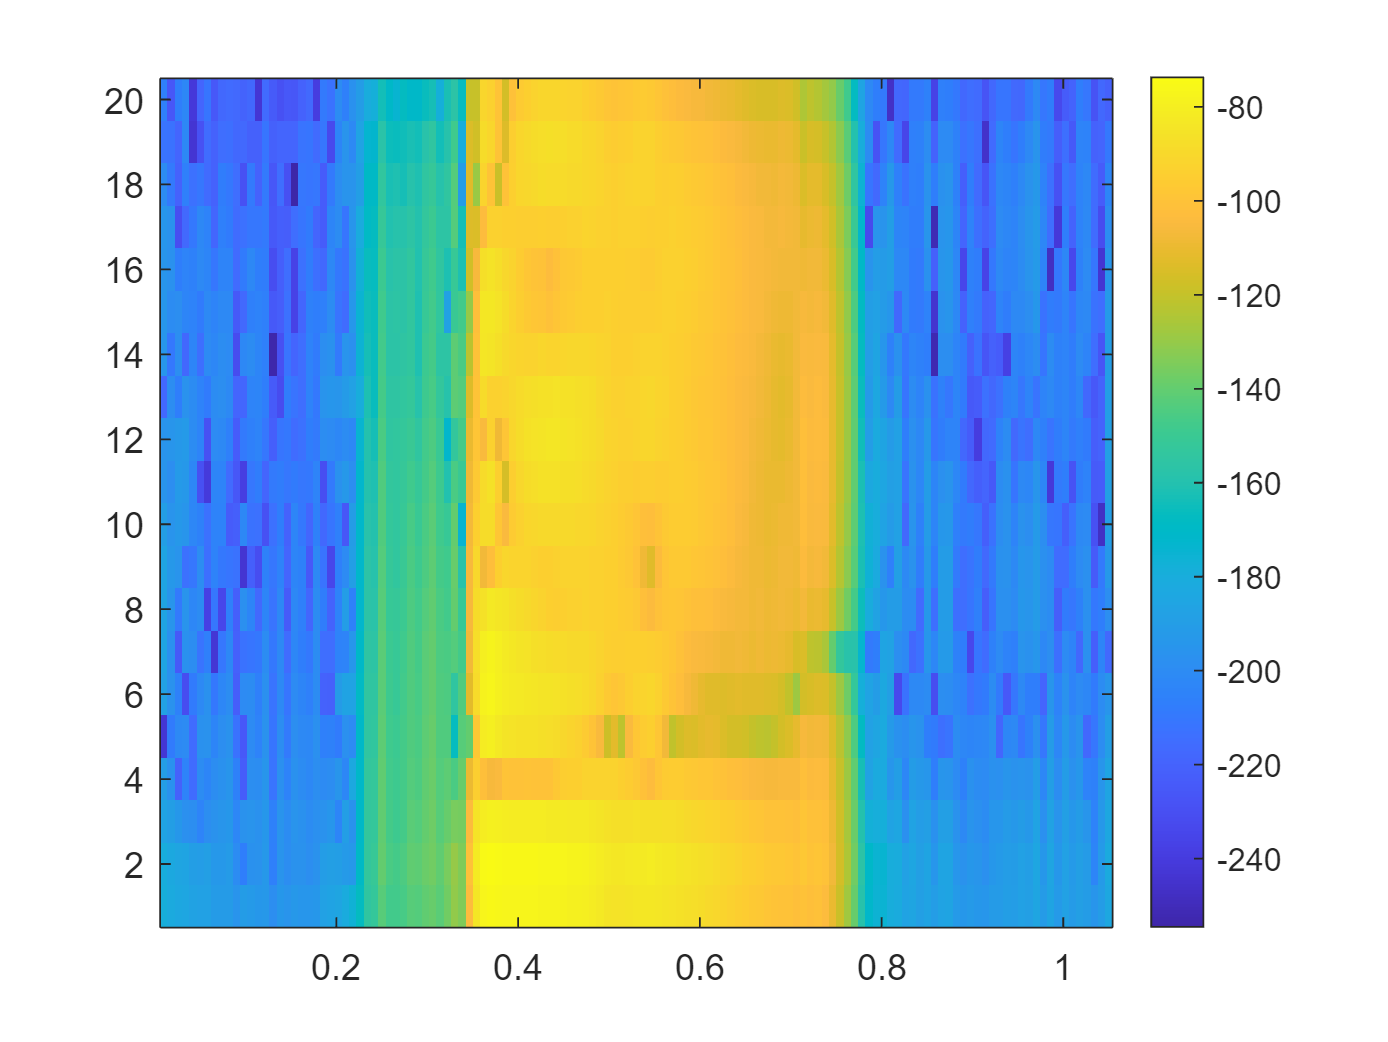

% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar

% end of dct part

% s4
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s4.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s5
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s5.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s6
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s6.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s7
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s7.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s8
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s8.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s9
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s9.wav');
[S,F,T] = stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s10
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s10.wav');
[S,F,T] = stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s11
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s11.wav');
[S,F,T] = stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

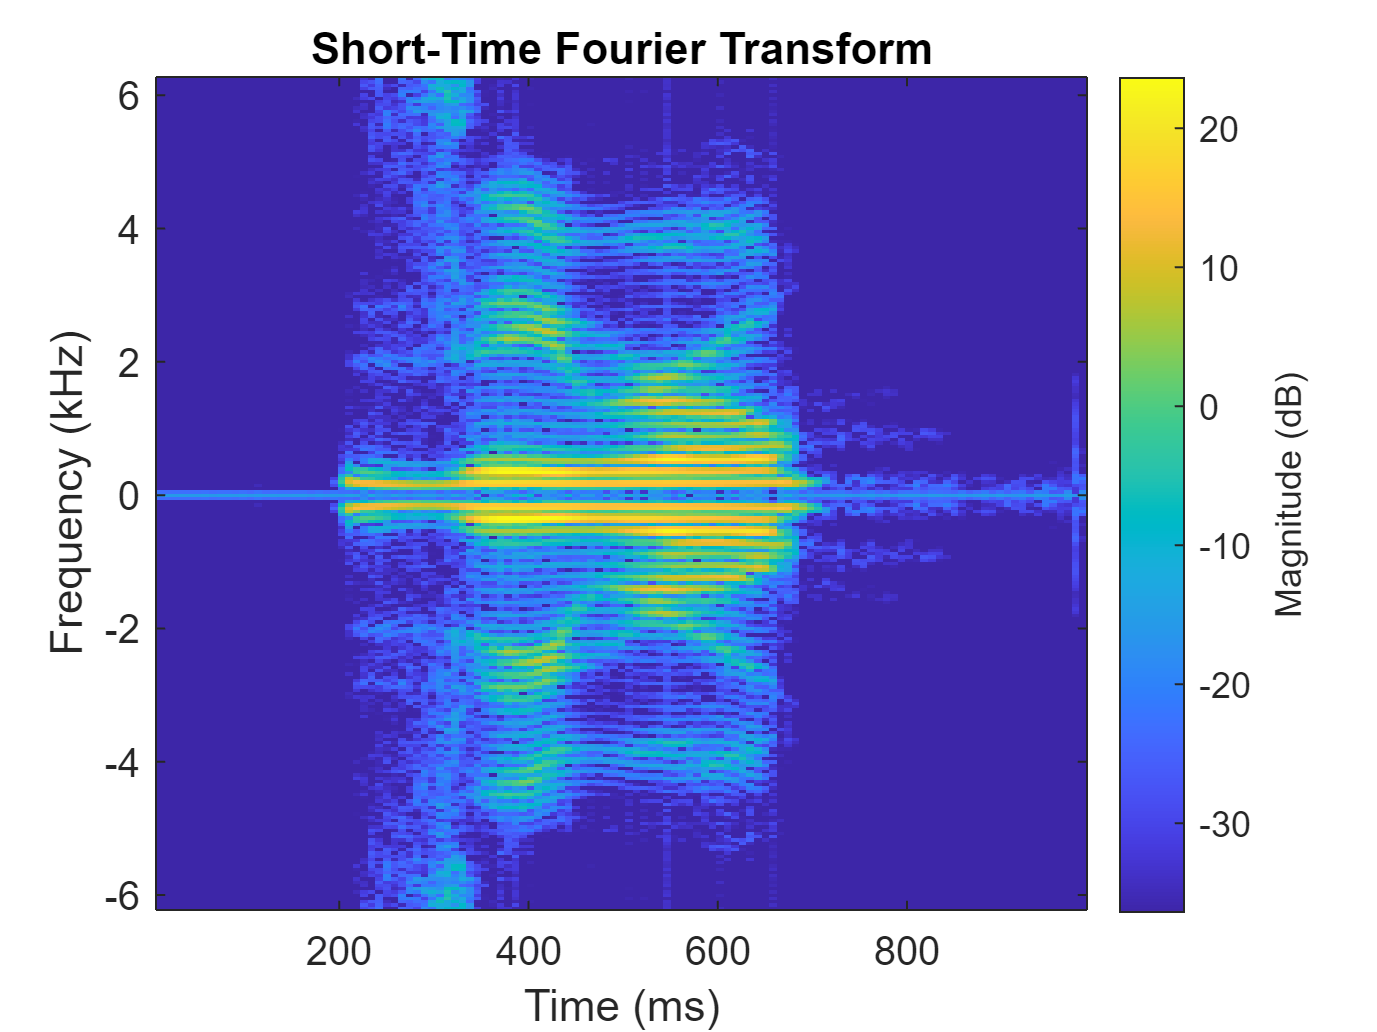

% Test s1
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Test_Data\s1.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)

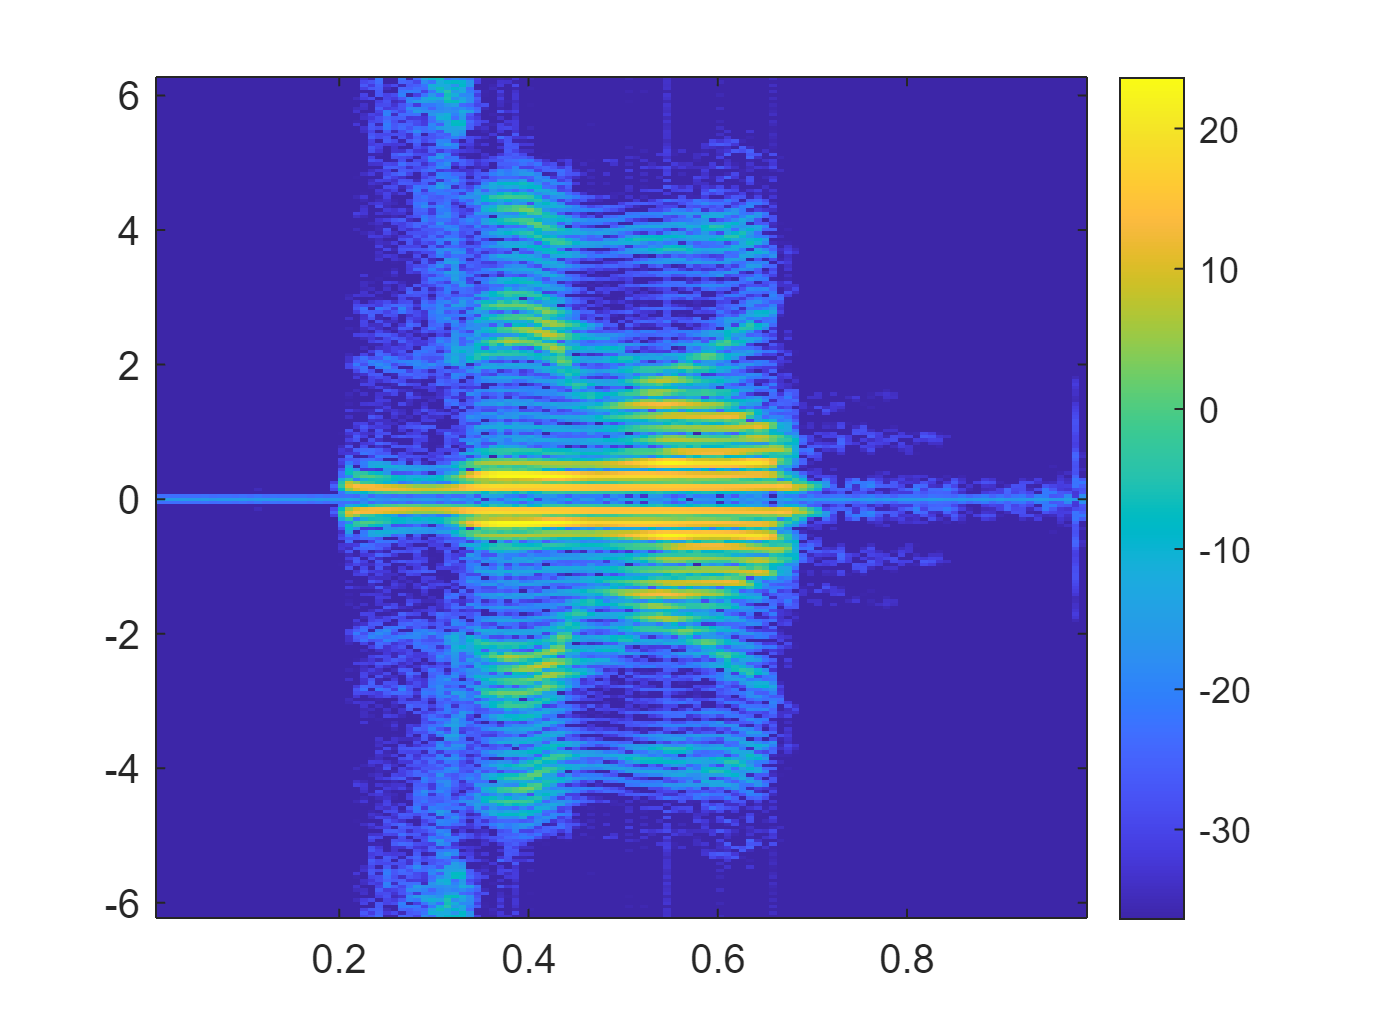

% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar

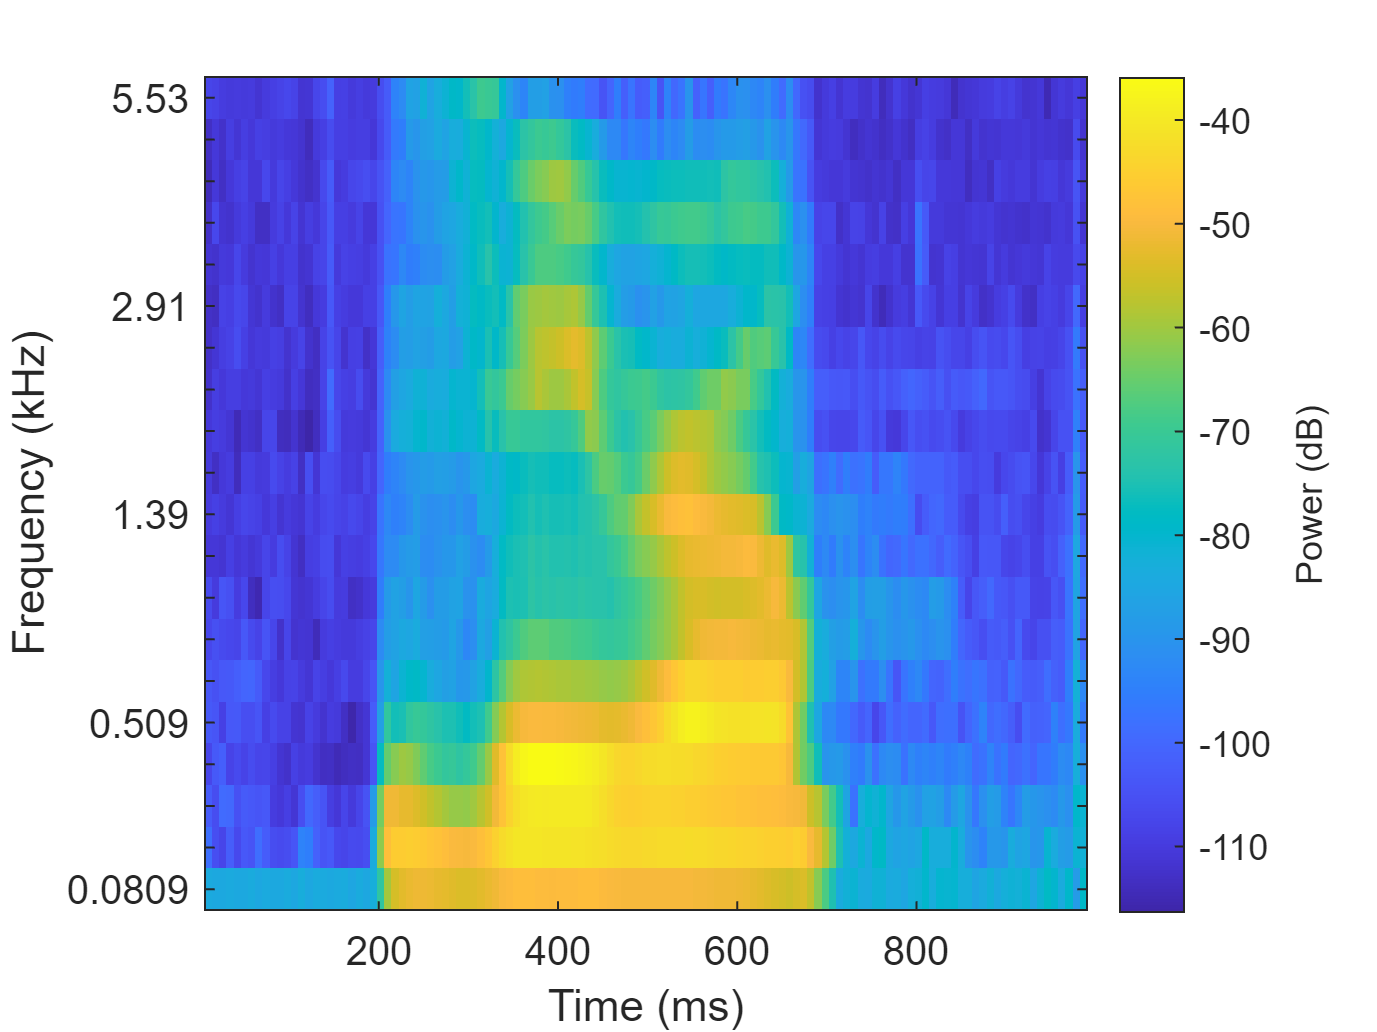

% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);

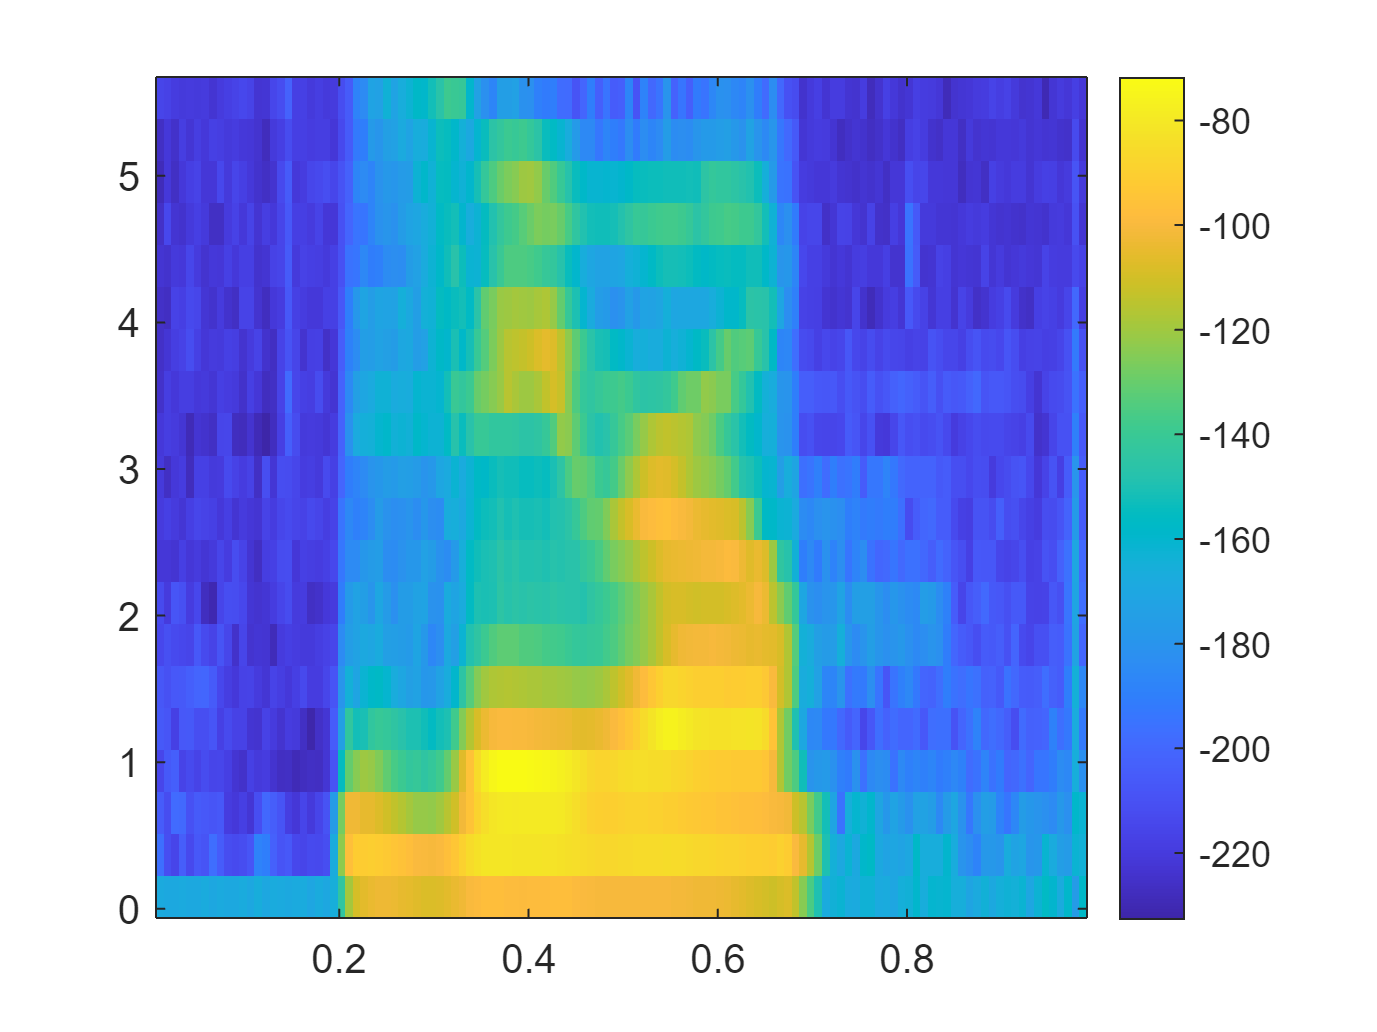

[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss));
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar

% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1));

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');

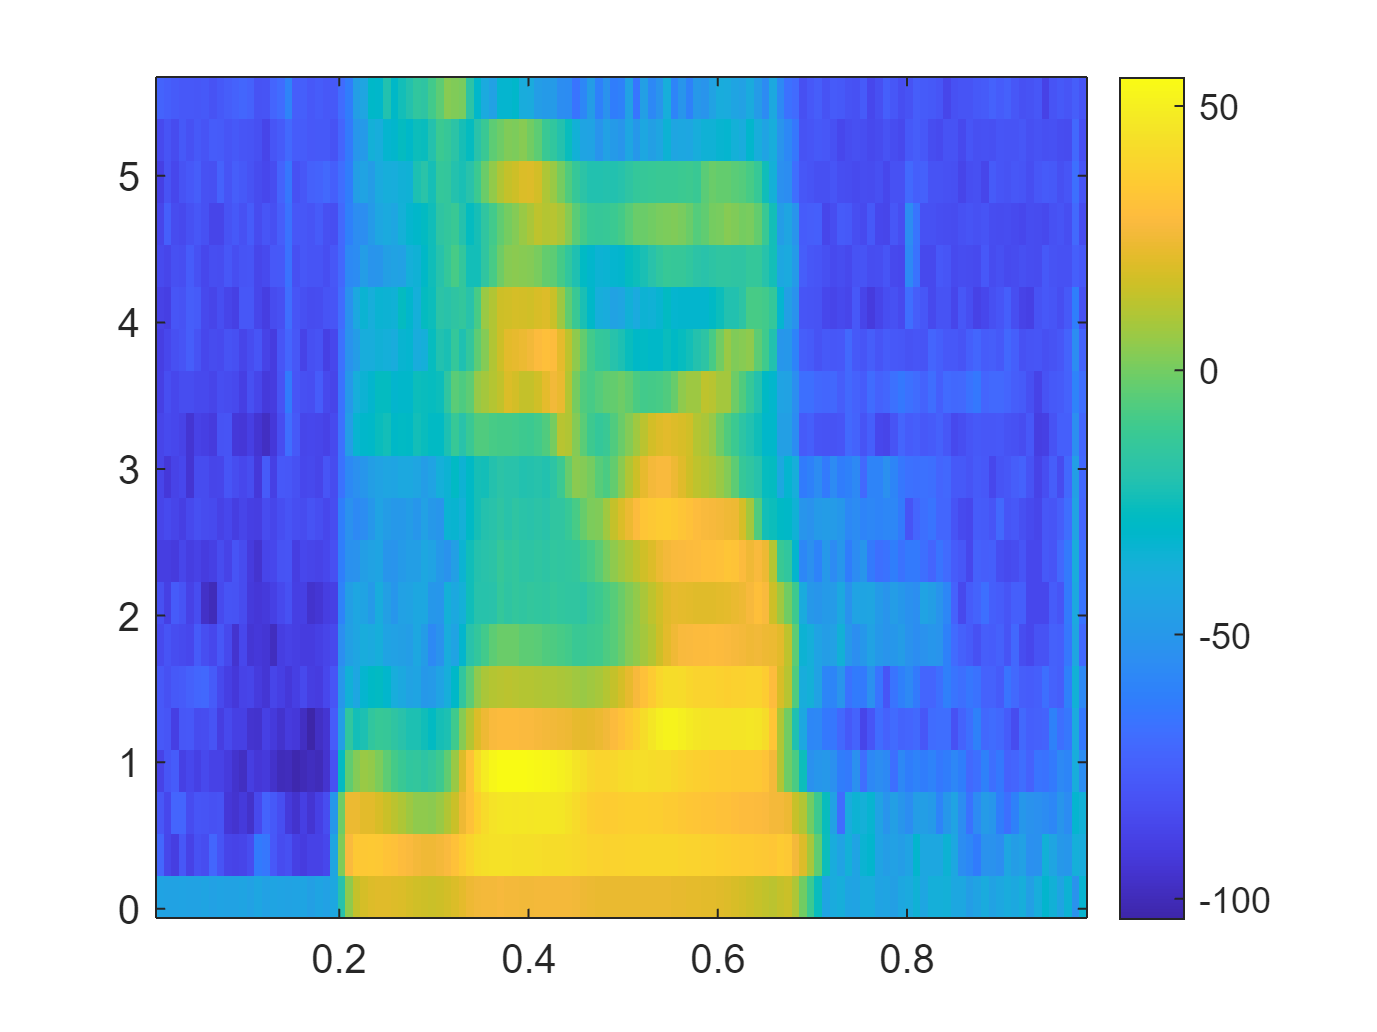

% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(n2-1:n)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some));
imagesc((T),(Ff/1000),some);
set(gca, 'YDir', 'normal');
view(2)
colorbar

some = some / 20;
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(some(:,i));
    if i == 1
        y = [f(2:end)];
    else
        y = [y f(2:end)];
    end
end
%sdb = mag2db(abs(y));
y1test = y;
newf = 1:1:20;
imagesc(Tt,(newf)',y11);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part
% 1. run test signal through MFCC get those points
% 2. compare those values against the centroids from train data
% 3. use diseu and then do values then get groups matrix and then all non zero
% values get average
% 4. get sA average against s1 then do sA average against s2; whichever is
% less that is the signal
distancesS1 = disteu(y1test,(clusters)'); % getting distances
[rd1,cd1] = size(distancesS1); % used to determine size for groups matrix
groupsS1 = zeros(rd1,cd1); % defining groups matrix (frames,numC)
% for loop for grouping
for i = 1:rd1
    holder = min(distancesS1(i,:));
    for j = 1:cd1
        if distancesS1(i,j) == holder
            groupsS1(i,j) = holder;
        end
    end
end
% end of for loop for grouping
avgS1 = zeros(1,cd1); % making distortion matrix (1,numCentroids)
% for loop for summing minimum distances
for i = 1:cd1
    avgS1(1,i) = sum(groupsS1(:,i)); % summing each column at a time; 1/(frames)
end
% end of for loop for summing minimum distances
avgS1 = (1/129)*sum(avgS1) % summing final rows of each group; this makes Do one value

avgS1 = 1.8578


distancesS2 = disteu(y1test,(clusters1)'); % getting distances
[rd2,cd2] = size(distancesS2); % used to determine size for groups matrix
groupsS2 = zeros(rd2,cd2); % defining groups matrix (frames,numC)
% for loop for grouping
for i = 1:rd2
    holder = min(distancesS2(i,:));
    for j = 1:cd2
        if distancesS2(i,j) == holder
            groupsS2(i,j) = holder;
        end
    end
end
% end of for loop for grouping
avgS2 = zeros(1,cd2); % making distortion matrix (1,numCentroids)
% for loop for summing minimum distances
for i = 1:cd2
    avgS2(1,i) = sum(groupsS2(:,i)); % summing each column at a time; 1/(frames)
end
% end of for loop for summing minimum distances
avgS2 = (1/134)*sum(avgS2) % summing final rows of each group; this makes Do one value

avgS2 = 2.3854

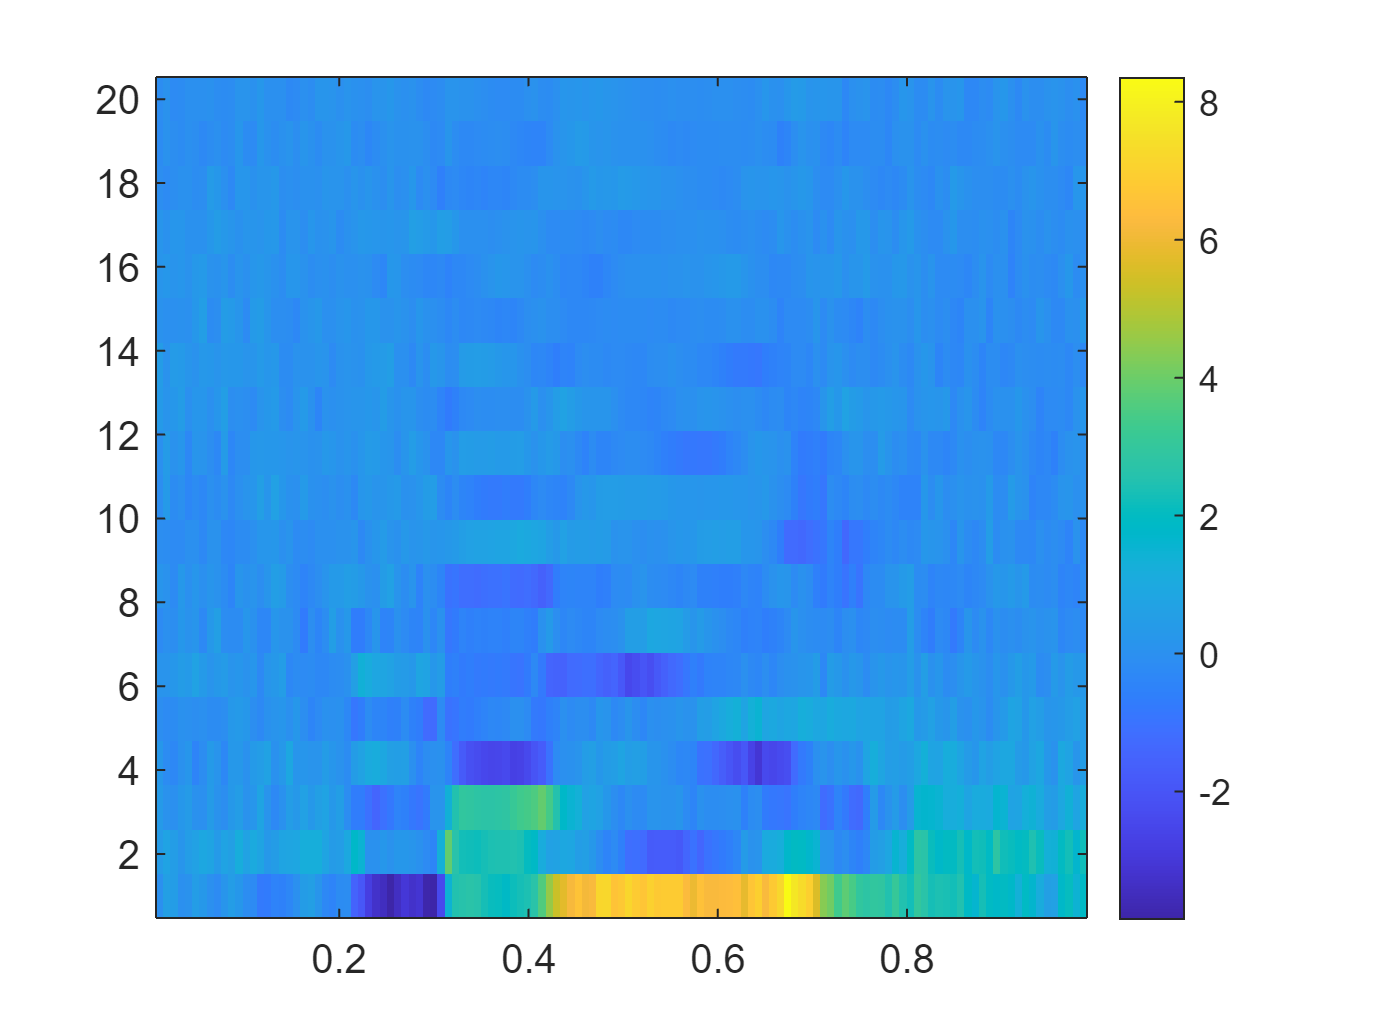


if avgS2 < avgS1
    print("Signal is S2")
else
    print("Signal is S1")
end